Эксперименты с ДПФ, с обычной обрезкой матрицы

% Загрузка файла и создание матрицы H из созданного датасета

% loaded_data = load('..\H_dataset_test_8_1_128.mat');
loaded_data = load('..\H_dataset_test_32_1_1024.mat');

H_dataset = loaded_data.H_dataset;
[num_samples, timeslots, num_tx_antennas, num_subcarriers] = size(H_dataset) 

num_samples = 5

timeslots = 10

num_tx_antennas = 32

num_subcarriers = 1024


truncationFactors = 2:2:(num_subcarriers/2);
hCorrelationValues = zeros(1, length(truncationFactors));
hNMSEValues = zeros(1, length(truncationFactors));

H_test_tranc = zeros(num_tx_antennas,num_subcarriers);

for i = 1:length(truncationFactors)
    truncationFactor = truncationFactors(i);

    midPoint = floor(num_subcarriers/2);
    lowerEdge = midPoint - (num_subcarriers-truncationFactor)/2 + 1;
    upperEdge = midPoint + (num_subcarriers-truncationFactor)/2;
    H_test_tranc = squeeze(H_dataset(1,1,:,:));
%     H_test_tranc = permute(H_test_tranc, [2 1]);

    HtruncReal = zeros(num_tx_antennas,truncationFactor, 2);
    Hdft2 = fft2(H_test_tranc(:, :));
    Htemp = Hdft2(:,[1:lowerEdge-1 upperEdge+1:end]);
    Htrunc = ifft2(Htemp);
    HtruncReal(:, :, 1) = real(Htrunc);
    HtruncReal(:, :, 2) = imag(Htrunc);
    
    Hhat = zeros(num_tx_antennas, num_subcarriers);
    Htrunc = complex(HtruncReal(:, :, 1), HtruncReal(:, :, 2));
    Htemp = fft2(Htrunc);
    Hfull = zeros(num_tx_antennas,num_subcarriers);
    Hfull(:, [1:lowerEdge-1 upperEdge+1:end]) = Htemp;
    Hhat(:, :) = ifft2(Hfull);

    hCorrelationValues(i) = hCorrelation(H_test_tranc, Hhat);
    hNMSEValues(i) = hNMSE(H_test_tranc, Hhat);
end

Матрица усечённая:

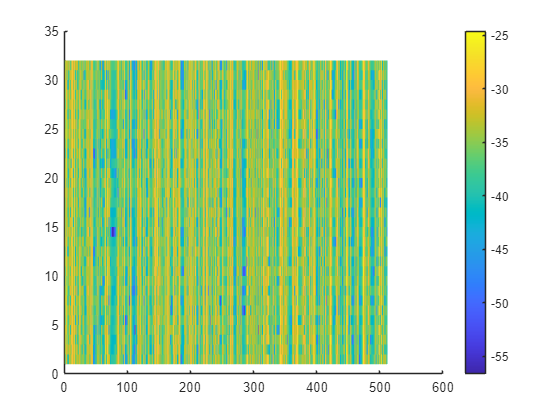

figure; clf; hold on;
surf(10*log10(abs(squeeze(Htemp(:,:)))), 'EdgeColor', 'none'); colorbar;

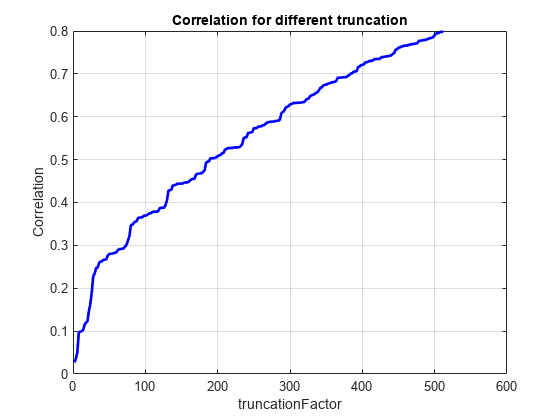

% вывод результатов

% Correlation
figure;
plot(truncationFactors, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('truncationFactor');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

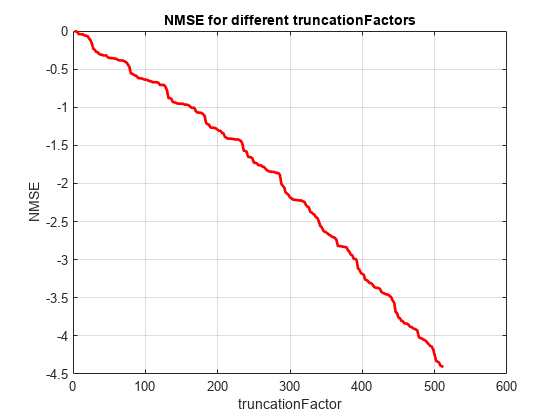

% NMSE
figure;
plot(truncationFactors, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('truncationFactor');
ylabel('NMSE');
title('NMSE for different truncationFactors');
grid on;

H_test_tranc = squeeze(H_dataset(1,1,:,:));

[U, S, V] = svd(H_test_tranc(:,:))

U =   -0.1311 + 0.0000i   0.1415 + 0.0000i  -0.0341 + 0.0000i   0.0835 + 0.0000i  -0.1261 + 0.0000i   0.1387 + 0.0000i   0.1736 + 0.0000i  -0.1750 + 0.0000i  -0.2225 + 0.0000i   0.4378 + 0.0000i   0.3730 + 0.0000i   0.1785 + 0.0000i  -0.4371 + 0.0000i  -0.1423 + 0.0000i   0.3852 + 0.0000i   0.0690 + 0.0000i  -0.1517 + 0.0000i  -0.0190 + 0.0000i  -0.0725 + 0.0000i  -0.0323 + 0.0000i  -0.0221 + 0.0000i   0.0924 + 0.0000i   0.0357 + 0.0000i  -0.0948 + 0.0000i  -0.0596 + 0.0000i   0.0701 + 0.0000i   0.0061 + 0.0000i   0.0253 + 0.0000i  -0.0568 + 0.0000i  -0.0304 + 0.0000i   0.0662 + 0.0000i  -0.1242 + 0.0000i
   0.1279 + 0.0145i  -0.2756 - 0.0174i  -0.1797 - 0.1661i  -0.0303 - 0.0220i   0.1128 - 0.0936i   0.1013 - 0.0083i   0.1906 + 0.2586i   0.1464 + 0.3598i   0.1325 + 0.0947i   0.2600 + 0.0517i   0.1040 + 0.1554i  -0.1278 - 0.2774i   0.3201 - 0.1256i  -0.1708 + 0.0839i   0.1023 - 0.1618i  -0.0389 + 0.1341i  -0.1257 + 0.0010i   0.0234 - 0.0520i   0.0354 + 0.0109i  -0.0941 + 0.0719i   0.01

S = 1.0e-03 *

    0.1225         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1202         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

V =    0.0202 + 0.0006i   0.0118 - 0.0099i  -0.0110 + 0.0059i  -0.0406 - 0.0314i  -0.0127 - 0.0013i   0.0024 - 0.0459i   0.0049 + 0.0147i  -0.0080 - 0.0126i  -0.0250 - 0.0095i  -0.0216 - 0.0137i  -0.0061 + 0.0411i  -0.0297 + 0.0474i   0.0271 + 0.0395i  -0.0161 + 0.0219i   0.0108 + 0.0305i   0.0001 + 0.0284i  -0.0160 + 0.0250i   0.0014 + 0.0186i   0.0171 + 0.0386i   0.0035 - 0.0113i  -0.0365 + 0.0220i  -0.0328 + 0.0143i   0.0122 - 0.0048i   0.0155 - 0.0440i  -0.0008 + 0.0089i  -0.0050 - 0.0028i  -0.0238 - 0.0123i  -0.0328 - 0.0095i   0.0219 + 0.0032i   0.0014 - 0.0050i  -0.0193 + 0.0170i  -0.0021 + 0.0200i  -0.0188 - 0.0105i   0.0159 - 0.0398i   0.0005 - 0.0000i   0.0033 - 0.0673i   0.0459 + 0.0033i   0.0056 - 0.0128i   0.0299 - 0.0160i   0.0343 - 0.0182i   0.0252 - 0.0172i  -0.0033 - 0.0050i   0.0114 + 0.0027i  -0.0026 - 0.0358i   0.0372 - 0.0340i  -0.0290 - 0.0004i   0.0035 - 0.0152i   0.0163 + 0.0048i   0.0251 + 0.0075i   0.0310 + 0.0143i
   0.0173 + 0.0086i  -0.0116 + 0.0197i  -0.01

% figure; clf; hold on;
% surf(10*log10(abs(squeeze(U))), 'EdgeColor', 'none'); view(0,90); colorbar;
% figure; clf; hold on;
% surf(abs(squeeze(U)), 'EdgeColor', 'none'); view(0,90); colorbar;

% figure; clf; hold on;
% surf(10*log10(abs(squeeze(S))), 'EdgeColor', 'none'); view(0,90); colorbar;

% figure; clf; hold on;
% surf(abs(squeeze(S)), 'EdgeColor', 'none'); view(0,90); colorbar;

% figure; clf; hold on;
% surf(10*log10(abs(squeeze(V))), 'EdgeColor', 'none'); view(0,90); colorbar;

% figure; clf; hold on;
% surf(abs(squeeze(V)), 'EdgeColor', 'none'); view(0,90); colorbar;



% dims = 2:2:size(H_test_tranc, 1);
dims = 1:size(H_test_tranc, 1);
comp_matrices = zeros(length(dims), size(H_test_tranc, 1), size(H_test_tranc, 2));

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(dims));
hNMSEValues = zeros(size(dims));

for i = 1:length(dims)
    r = dims(i);
    comp_matrices(i, :, :) = U(:, 1:r) * S(1:r, 1:r) * V(:, 1:r)';
    
    CorrelationValues = hCorrelation(H_test_tranc, squeeze(comp_matrices(i,:,:)));
    NMSEValues = hNMSE(H_test_tranc, squeeze(comp_matrices(i,:,:)));

    % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
    
    % Вывод или сохранение метрик по необходимости
    disp(['Metrics for reconstructed complex matrix with ', num2str(r), ' components']);
    disp(['Correlation: ', num2str(CorrelationValues)]);
    disp(['NMSE: ', num2str(NMSEValues)]);
end

Metrics for reconstructed complex matrix with 1 components


Correlation: 0.22122


NMSE: -0.21792


Metrics for reconstructed complex matrix with 2 components


Correlation: 0.31002


NMSE: -0.43885


Metrics for reconstructed complex matrix with 3 components


Correlation: 0.37583


NMSE: -0.66134


Metrics for reconstructed complex matrix with 4 components


Correlation: 0.42985


NMSE: -0.88719


Metrics for reconstructed complex matrix with 5 components


Correlation: 0.47695


NMSE: -1.1209


Metrics for reconstructed complex matrix with 6 components


Correlation: 0.51795


NMSE: -1.3565


Metrics for reconstructed complex matrix with 7 components


Correlation: 0.55462


NMSE: -1.5965


Metrics for reconstructed complex matrix with 8 components


Correlation: 0.58859


NMSE: -1.8471


Metrics for reconstructed complex matrix with 9 components


Correlation: 0.61973


NMSE: -2.1046


Metrics for reconstructed complex matrix with 10 components


Correlation: 0.64807


NMSE: -2.3657


Metrics for reconstructed complex matrix with 11 components


Correlation: 0.67494


NMSE: -2.6403


Metrics for reconstructed complex matrix with 12 components


Correlation: 0.70024


NMSE: -2.9271


Metrics for reconstructed complex matrix with 13 components


Correlation: 0.72433


NMSE: -3.2298


Metrics for reconstructed complex matrix with 14 components


Correlation: 0.74656


NMSE: -3.5394


Metrics for reconstructed complex matrix with 15 components


Correlation: 0.76724


NMSE: -3.858


Metrics for reconstructed complex matrix with 16 components


Correlation: 0.78719


NMSE: -4.1984


Metrics for reconstructed complex matrix with 17 components


Correlation: 0.8058


NMSE: -4.5508


Metrics for reconstructed complex matrix with 18 components


Correlation: 0.82357


NMSE: -4.925


Metrics for reconstructed complex matrix with 19 components


Correlation: 0.84063


NMSE: -5.3262


Metrics for reconstructed complex matrix with 20 components


Correlation: 0.85683


NMSE: -5.7536


Metrics for reconstructed complex matrix with 21 components


Correlation: 0.87228


NMSE: -6.2136


Metrics for reconstructed complex matrix with 22 components


Correlation: 0.88712


NMSE: -6.7157


Metrics for reconstructed complex matrix with 23 components


Correlation: 0.90108


NMSE: -7.2571


Metrics for reconstructed complex matrix with 24 components


Correlation: 0.91413


NMSE: -7.8419


Metrics for reconstructed complex matrix with 25 components


Correlation: 0.92662


NMSE: -8.4961


Metrics for reconstructed complex matrix with 26 components


Correlation: 0.93869


NMSE: -9.2496


Metrics for reconstructed complex matrix with 27 components


Correlation: 0.9504


NMSE: -10.1437


Metrics for reconstructed complex matrix with 28 components


Correlation: 0.96143


NMSE: -11.2115


Metrics for reconstructed complex matrix with 29 components


Correlation: 0.97171


NMSE: -12.5354


Metrics for reconstructed complex matrix with 30 components


Correlation: 0.98174


NMSE: -14.4153


Metrics for reconstructed complex matrix with 31 components


Correlation: 0.99125


NMSE: -17.5869


Metrics for reconstructed complex matrix with 32 components


Correlation: 1


NMSE: -295.4321


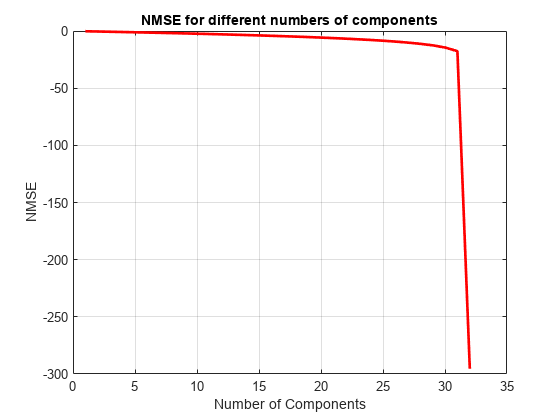


% Построение графика для NMSE
figure;
plot(dims, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

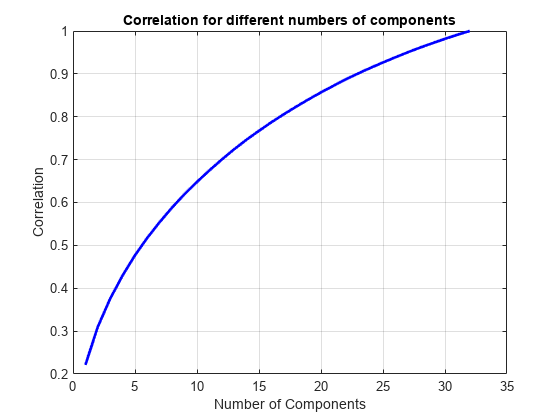

% Построение графика для корреляции
figure;
plot(dims, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;

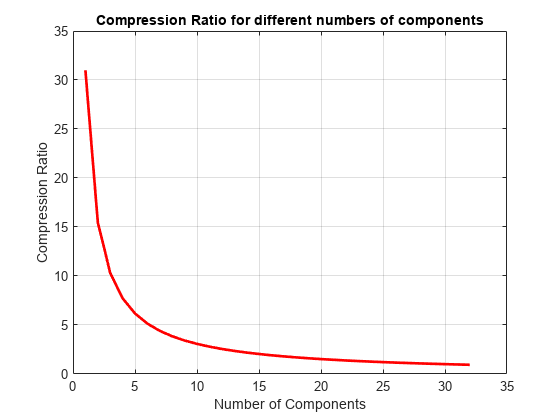

% Количество элементов в исходной матрице
original_elements = numel(H_test_tranc);

% Количество элементов для каждого r
compressed_elements = zeros(size(dims));
for i = 1:length(dims)
    r = dims(i);
    
    % Количество элементов для хранения сжатой матрицы
    num_elements = numel(U(:, 1:r)) + numel(S(1:r, 1:r)) + numel(V(:, 1:r)');
    compressed_elements(i) = num_elements;
end

% Во сколько раз происходит сжатие
compression_ratio = original_elements ./ compressed_elements;

% Построение графика
figure;
plot(dims, compression_ratio, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Compression Ratio');
title('Compression Ratio for different numbers of components');
grid on;

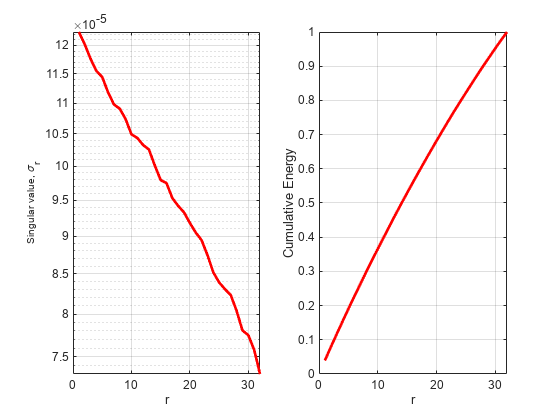

figure, subplot(1,2,1)
semilogy(diag(S),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Singular value, \sigma_r') 
subplot(1,2,2)
plot(cumsum(diag(S))/sum(diag(S)),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Cumulative Energy')

Вывод графиков для разного количества оставляемых компонент (2..32)

% figure; clf; hold on;
% H_samp = squeeze(comp_matrices);
% for i = 1:length(dims)
%     subplot(length(dims)/4,4,i);
%     surf(abs(squeeze(H_samp(i,:,:))), 'EdgeColor', 'none'); colorbar;
%     view(0,90);
%     title(sprintf("{%d}", i));
% end


H_test_tranc = squeeze(H_dataset(1,1,:,:));
[U, S, V] = svd(fft2(H_test_tranc(:,:)))

U =   -0.1002 + 0.0000i   0.2440 + 0.0000i  -0.0264 + 0.0000i   0.1659 + 0.0000i  -0.3183 + 0.0000i   0.2008 + 0.0000i   0.1867 + 0.0000i  -0.2195 + 0.0000i  -0.2262 + 0.0000i   0.2509 + 0.0000i   0.0913 + 0.0000i  -0.0270 + 0.0000i  -0.1459 + 0.0000i  -0.0699 + 0.0000i  -0.2923 + 0.0000i   0.1102 + 0.0000i   0.0991 + 0.0000i   0.1802 + 0.0000i  -0.2364 + 0.0000i  -0.2059 + 0.0000i  -0.1196 + 0.0000i   0.1588 + 0.0000i   0.1526 + 0.0000i   0.1548 + 0.0000i  -0.1061 + 0.0000i  -0.2141 + 0.0000i   0.1891 + 0.0000i   0.0947 + 0.0000i   0.1326 + 0.0000i  -0.1584 + 0.0000i   0.1395 + 0.0000i  -0.1979 + 0.0000i
  -0.0431 + 0.0201i   0.0961 - 0.2103i  -0.0331 + 0.0976i   0.1353 + 0.0130i  -0.0665 + 0.2312i   0.0871 - 0.1324i  -0.1387 - 0.0235i   0.0192 + 0.1532i   0.2168 + 0.2331i   0.0639 - 0.2021i  -0.1386 + 0.0727i  -0.0851 - 0.0299i   0.0235 + 0.1048i   0.0784 - 0.0831i   0.0586 - 0.1295i  -0.0438 - 0.1459i  -0.0189 - 0.0189i   0.0212 + 0.0727i  -0.0410 - 0.0638i   0.1301 + 0.0471i   0.07

S =     0.0222         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0218         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    0.0083 - 0.0252i   0.0437 + 0.0421i  -0.0182 + 0.0364i  -0.0146 + 0.0115i  -0.0017 - 0.0321i  -0.0096 - 0.0010i  -0.0207 - 0.0003i   0.0002 - 0.0076i   0.0034 + 0.0053i   0.0188 - 0.0018i  -0.0016 - 0.0056i   0.0223 - 0.0097i   0.0093 + 0.0383i   0.0223 - 0.0146i  -0.0101 + 0.0318i  -0.0076 + 0.0206i   0.0057 + 0.0285i  -0.0177 + 0.0317i   0.0066 - 0.0127i   0.0156 + 0.0122i  -0.0163 + 0.0102i  -0.0054 - 0.0013i   0.0123 + 0.0167i  -0.0118 + 0.0020i  -0.0030 - 0.0002i  -0.0198 - 0.0162i  -0.0028 - 0.0024i  -0.0018 + 0.0108i   0.0034 + 0.0106i  -0.0101 - 0.0020i   0.0132 + 0.0093i  -0.0206 + 0.0071i  -0.0051 - 0.0049i  -0.0052 - 0.0076i  -0.0090 - 0.0132i   0.0460 - 0.0077i  -0.0151 + 0.0120i   0.0147 - 0.0291i  -0.0245 - 0.0068i  -0.0037 + 0.0150i  -0.0166 + 0.0031i  -0.0589 - 0.0113i   0.0589 + 0.0211i   0.0281 + 0.0119i  -0.0630 - 0.0214i   0.0005 + 0.0014i   0.0022 + 0.0015i   0.0026 + 0.0007i   0.0095 - 0.0062i  -0.0024 + 0.0010i
  -0.0061 + 0.0054i  -0.0089 - 0.0039i   0.00

dims = 1:size(H_test_tranc, 1);
comp_matrices = zeros(length(dims), size(H_test_tranc, 1), size(H_test_tranc, 2));

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(dims));
hNMSEValues = zeros(size(dims));

for i = 1:length(dims)
    r = dims(i);
    comp_matrices(i, :, :) = U(:, 1:r) * S(1:r, 1:r) * V(:, 1:r)';
    
    CorrelationValues = hCorrelation(H_test_tranc, ifft2(squeeze(comp_matrices(i,:,:))));
    NMSEValues = hNMSE(H_test_tranc, ifft2(squeeze(comp_matrices(i,:,:))));

    % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
    
    % Вывод или сохранение метрик по необходимости
    disp(['Metrics for reconstructed complex matrix with ', num2str(r), ' components']);
    disp(['Correlation: ', num2str(CorrelationValues)]);
    disp(['NMSE: ', num2str(NMSEValues)]);
end

Metrics for reconstructed complex matrix with 1 components


Correlation: 0.22122


NMSE: -0.21792


Metrics for reconstructed complex matrix with 2 components


Correlation: 0.31002


NMSE: -0.43885


Metrics for reconstructed complex matrix with 3 components


Correlation: 0.37583


NMSE: -0.66134


Metrics for reconstructed complex matrix with 4 components


Correlation: 0.42985


NMSE: -0.88719


Metrics for reconstructed complex matrix with 5 components


Correlation: 0.47695


NMSE: -1.1209


Metrics for reconstructed complex matrix with 6 components


Correlation: 0.51795


NMSE: -1.3565


Metrics for reconstructed complex matrix with 7 components


Correlation: 0.55462


NMSE: -1.5965


Metrics for reconstructed complex matrix with 8 components


Correlation: 0.58859


NMSE: -1.8471


Metrics for reconstructed complex matrix with 9 components


Correlation: 0.61973


NMSE: -2.1046


Metrics for reconstructed complex matrix with 10 components


Correlation: 0.64807


NMSE: -2.3657


Metrics for reconstructed complex matrix with 11 components


Correlation: 0.67494


NMSE: -2.6403


Metrics for reconstructed complex matrix with 12 components


Correlation: 0.70024


NMSE: -2.9271


Metrics for reconstructed complex matrix with 13 components


Correlation: 0.72433


NMSE: -3.2298


Metrics for reconstructed complex matrix with 14 components


Correlation: 0.74656


NMSE: -3.5394


Metrics for reconstructed complex matrix with 15 components


Correlation: 0.76724


NMSE: -3.858


Metrics for reconstructed complex matrix with 16 components


Correlation: 0.78719


NMSE: -4.1984


Metrics for reconstructed complex matrix with 17 components


Correlation: 0.8058


NMSE: -4.5508


Metrics for reconstructed complex matrix with 18 components


Correlation: 0.82357


NMSE: -4.925


Metrics for reconstructed complex matrix with 19 components


Correlation: 0.84063


NMSE: -5.3262


Metrics for reconstructed complex matrix with 20 components


Correlation: 0.85683


NMSE: -5.7536


Metrics for reconstructed complex matrix with 21 components


Correlation: 0.87228


NMSE: -6.2136


Metrics for reconstructed complex matrix with 22 components


Correlation: 0.88712


NMSE: -6.7157


Metrics for reconstructed complex matrix with 23 components


Correlation: 0.90108


NMSE: -7.2571


Metrics for reconstructed complex matrix with 24 components


Correlation: 0.91413


NMSE: -7.8419


Metrics for reconstructed complex matrix with 25 components


Correlation: 0.92662


NMSE: -8.4961


Metrics for reconstructed complex matrix with 26 components


Correlation: 0.93869


NMSE: -9.2496


Metrics for reconstructed complex matrix with 27 components


Correlation: 0.9504


NMSE: -10.1437


Metrics for reconstructed complex matrix with 28 components


Correlation: 0.96143


NMSE: -11.2115


Metrics for reconstructed complex matrix with 29 components


Correlation: 0.97171


NMSE: -12.5354


Metrics for reconstructed complex matrix with 30 components


Correlation: 0.98174


NMSE: -14.4153


Metrics for reconstructed complex matrix with 31 components


Correlation: 0.99125


NMSE: -17.5869


Metrics for reconstructed complex matrix with 32 components


Correlation: 1


NMSE: -294.1559


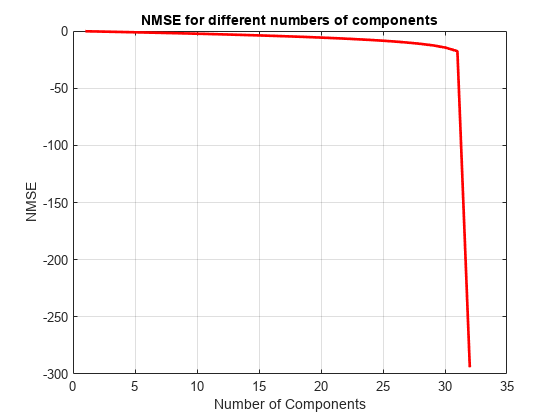

% Построение графика для NMSE
figure;
plot(dims, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

% Построение графика для корреляции
figure;
plot(dims, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;


% Количество элементов в исходной матрице
original_elements = numel(H_test_tranc);

% Количество элементов для каждого r
compressed_elements = zeros(size(dims));
for i = 1:length(dims)
    r = dims(i);
    
    % Количество элементов для хранения сжатой матрицы
    num_elements = numel(U(:, 1:r)) + numel(S(1:r, 1:r)) + numel(V(:, 1:r)');
    compressed_elements(i) = num_elements;
end

% Во сколько раз происходит сжатие
compression_ratio = original_elements ./ compressed_elements;

% Построение графика
figure;
plot(dims, compression_ratio, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Compression Ratio');
title('Compression Ratio for different numbers of components');
grid on;

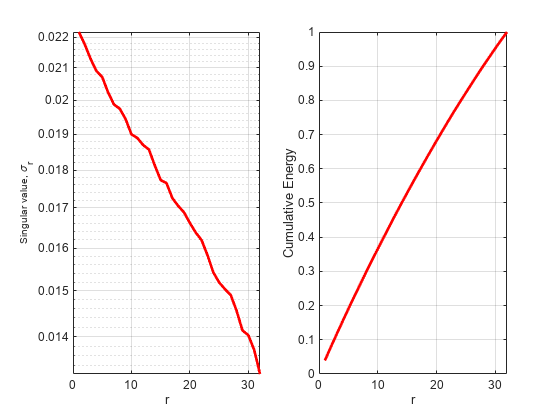


figure, subplot(1,2,1)
semilogy(diag(S),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Singular value, \sigma_r') 
subplot(1,2,2)
plot(cumsum(diag(S))/sum(diag(S)),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Cumulative Energy')


% Разделение на реальную и мнимую части
H_test_tranc_real = real(H_test_tranc);
H_test_tranc_imag = imag(H_test_tranc);

% Анализ сжатия для обоих частей
dims = 1:size(H_test_tranc_real, 1);

comp_matrices_complex = zeros(length(dims), size(H_test_tranc, 1), size(H_test_tranc, 2));


% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(dims));
hNMSEValues = zeros(size(dims));

for i = 1:length(dims)
    r = dims(i);
    
    % Сжатие реальной части
    [U_real, S_real, V_real] = svd(H_test_tranc_real);
    comp_matrix_real = U_real(:, 1:r) * S_real(1:r, 1:r) * V_real(:, 1:r)';
    
    % Сжатие мнимой части
    [U_imag, S_imag, V_imag] = svd(H_test_tranc_imag);
    comp_matrix_imag = U_imag(:, 1:r) * S_imag(1:r, 1:r) * V_imag(:, 1:r)';
    
    % Объединение в комплексное число
    comp_matrix = comp_matrix_real + 1i * comp_matrix_imag;

    CorrelationValues = hCorrelation(H_test_tranc, comp_matrix);
    NMSEValues = hNMSE(H_test_tranc, comp_matrix);
    
     % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
    
    % Вывод или сохранение метрик по необходимости
    disp(['Metrics for reconstructed complex matrix with ', num2str(r), ' components']);
    disp(['Correlation: ', num2str(CorrelationValues)]);
    disp(['NMSE: ', num2str(NMSEValues)]);
    
    % Сохранение в массив
    comp_matrices_complex(i, :, :) = comp_matrix;
    
%     % Вывод графика для сжатой комплексной матрицы
%     figure; clf; hold on;
%     surf(abs(squeeze(comp_matrices_complex(i,:,:))), 'EdgeColor', 'none'); colorbar;
%     title(['Compressed complex matrix with ', num2str(r), ' components']);
%     xlabel('X');
%     ylabel('Y');
%     zlabel('Magnitude (dB)');
%     view(0,90);
end

Metrics for reconstructed complex matrix with 1 components


Correlation: 0.22347


NMSE: -0.22238


Metrics for reconstructed complex matrix with 2 components


Correlation: 0.31162


NMSE: -0.44358


Metrics for reconstructed complex matrix with 3 components


Correlation: 0.37768


NMSE: -0.66835


Metrics for reconstructed complex matrix with 4 components


Correlation: 0.43091


NMSE: -0.89197


Metrics for reconstructed complex matrix with 5 components


Correlation: 0.47689


NMSE: -1.1205


Metrics for reconstructed complex matrix with 6 components


Correlation: 0.51795


NMSE: -1.3564


Metrics for reconstructed complex matrix with 7 components


Correlation: 0.55571


NMSE: -1.6039


Metrics for reconstructed complex matrix with 8 components


Correlation: 0.58968


NMSE: -1.8554


Metrics for reconstructed complex matrix with 9 components


Correlation: 0.62077


NMSE: -2.1135


Metrics for reconstructed complex matrix with 10 components


Correlation: 0.64961


NMSE: -2.3804


Metrics for reconstructed complex matrix with 11 components


Correlation: 0.67686


NMSE: -2.6607


Metrics for reconstructed complex matrix with 12 components


Correlation: 0.70186


NMSE: -2.9458


Metrics for reconstructed complex matrix with 13 components


Correlation: 0.72539


NMSE: -3.2432


Metrics for reconstructed complex matrix with 14 components


Correlation: 0.74788


NMSE: -3.5577


Metrics for reconstructed complex matrix with 15 components


Correlation: 0.76906


NMSE: -3.8865


Metrics for reconstructed complex matrix with 16 components


Correlation: 0.78883


NMSE: -4.2271


Metrics for reconstructed complex matrix with 17 components


Correlation: 0.80749


NMSE: -4.5839


Metrics for reconstructed complex matrix with 18 components


Correlation: 0.82545


NMSE: -4.9661


Metrics for reconstructed complex matrix with 19 components


Correlation: 0.84255


NMSE: -5.3734


Metrics for reconstructed complex matrix with 20 components


Correlation: 0.85855


NMSE: -5.8011


Metrics for reconstructed complex matrix with 21 components


Correlation: 0.8738


NMSE: -6.2615


Metrics for reconstructed complex matrix with 22 components


Correlation: 0.88824


NMSE: -6.7559


Metrics for reconstructed complex matrix with 23 components


Correlation: 0.90178


NMSE: -7.2854


Metrics for reconstructed complex matrix with 24 components


Correlation: 0.91484


NMSE: -7.8756


Metrics for reconstructed complex matrix with 25 components


Correlation: 0.92723


NMSE: -8.5311


Metrics for reconstructed complex matrix with 26 components


Correlation: 0.93914


NMSE: -9.2805


Metrics for reconstructed complex matrix with 27 components


Correlation: 0.95052


NMSE: -10.1542


Metrics for reconstructed complex matrix with 28 components


Correlation: 0.9615


NMSE: -11.2193


Metrics for reconstructed complex matrix with 29 components


Correlation: 0.97194


NMSE: -12.57


Metrics for reconstructed complex matrix with 30 components


Correlation: 0.98178


NMSE: -14.4229


Metrics for reconstructed complex matrix with 31 components


Correlation: 0.991


NMSE: -17.4652


Metrics for reconstructed complex matrix with 32 components


Correlation: 1


NMSE: -295.1556


% Построение графика для NMSE


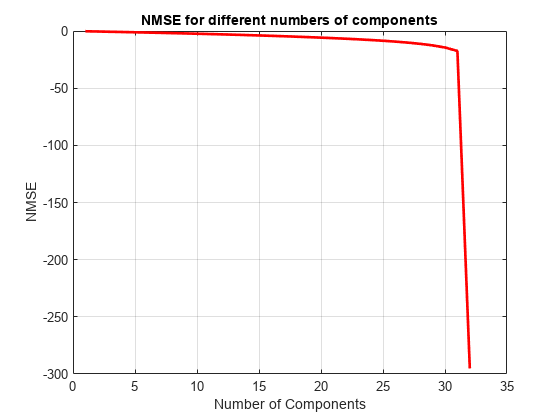

figure;
plot(dims, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

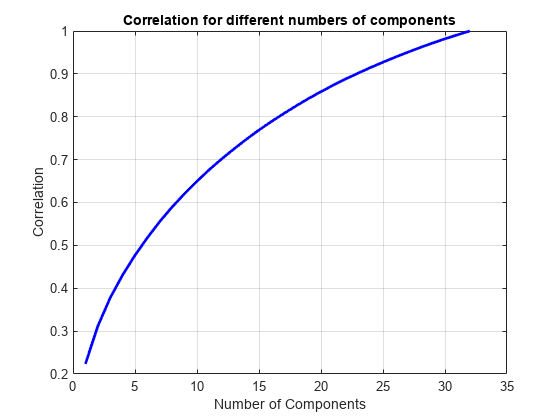

% Построение графика для корреляции
figure;
plot(dims, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;

% Количество элементов в исходной матрице
original_elements = numel(H_test_tranc);

% Количество элементов для каждого r
compressed_elements = zeros(size(dims));
for i = 1:length(dims)
    r = dims(i);
    
    % Количество элементов для хранения сжатой матрицы
    num_elements = numel(U_real(:, 1:r)) + numel(S_real(1:r, 1:r)) + numel(V_real(:, 1:r)');
    compressed_elements(i) = num_elements;
end

% Во сколько раз происходит сжатие
compression_ratio = original_elements ./ compressed_elements;

% Построение графика
figure;
plot(dims, compression_ratio, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Compression Ratio');
title('Compression Ratio for different numbers of components');
grid on;

% figure, subplot(1,2,1)
% semilogy(diag(S),'r-','LineWidth',2), grid on 
% xlabel('r')
% ylabel('Singular value, \sigma_r') 
% subplot(1,2,2)
% plot(cumsum(diag(S))/sum(diag(S)),'r-','LineWidth',2), grid on 
% xlabel('r')
% ylabel('Cumulative Energy')


H_test_tranc = squeeze(H_dataset(1,1,:,:));
H_test_tranc_real = real(H_test_tranc);
H_test_tranc_imag = imag(H_test_tranc);

% Анализ сжатия для обоих частей
dims = 1:size(H_test_tranc_real, 1) - 1;

comp_matrices_complex = zeros(length(dims), size(H_test_tranc, 1), size(H_test_tranc, 2));

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(dims));
hNMSEValues = zeros(size(dims));

for i = 1:length(dims)
    r = dims(i);
    
    % Сжатие реальной части с помощью PCA
    [coeff_real, score_real, ~, ~, explained_real] = pca(H_test_tranc_real);
    comp_matrix_real = score_real(:, 1:r) * coeff_real(:, 1:r)';
    
    % Сжатие мнимой части с помощью PCA
    [coeff_imag, score_imag, ~, ~, explained_imag] = pca(H_test_tranc_imag);
    comp_matrix_imag = score_imag(:, 1:r) * coeff_imag(:, 1:r)';
    
    % Объединение в комплексное число
    comp_matrix = comp_matrix_real + 1i * comp_matrix_imag;

    CorrelationValues = hCorrelation(H_test_tranc, comp_matrix);
    NMSEValues = hNMSE(H_test_tranc, comp_matrix);
    
    % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
    
    % Вывод или сохранение метрик по необходимости
    disp(['Metrics for reconstructed complex matrix with ', num2str(r), ' components']);
    disp(['Correlation: ', num2str(CorrelationValues)]);
    disp(['NMSE: ', num2str(NMSEValues)]);
    
    % Сохранение в массив
    comp_matrices_complex(i, :, :) = comp_matrix;
    
%     % Вывод графика для сжатой комплексной матрицы
%     figure; clf; hold on;
%     surf(abs(squeeze(comp_matrices_complex(i,:,:))), 'EdgeColor', 'none'); colorbar;
%     title(['Compressed complex matrix with ', num2str(r), ' components']);
%     xlabel('X');
%     ylabel('Y');
%     zlabel('Magnitude (dB)');
%     view(0,90);
end

Metrics for reconstructed complex matrix with 1 components


Correlation: 0.22219


NMSE: -0.21983


Metrics for reconstructed complex matrix with 2 components


Correlation: 0.30999


NMSE: -0.43876


Metrics for reconstructed complex matrix with 3 components


Correlation: 0.37633


NMSE: -0.6632


Metrics for reconstructed complex matrix with 4 components


Correlation: 0.42891


NMSE: -0.88287


Metrics for reconstructed complex matrix with 5 components


Correlation: 0.47434


NMSE: -1.107


Metrics for reconstructed complex matrix with 6 components


Correlation: 0.51557


NMSE: -1.3419


Metrics for reconstructed complex matrix with 7 components


Correlation: 0.5524


NMSE: -1.5809


Metrics for reconstructed complex matrix with 8 components


Correlation: 0.58605


NMSE: -1.8273


Metrics for reconstructed complex matrix with 9 components


Correlation: 0.61729


NMSE: -2.0832


Metrics for reconstructed complex matrix with 10 components


Correlation: 0.64621


NMSE: -2.3473


Metrics for reconstructed complex matrix with 11 components


Correlation: 0.67318


NMSE: -2.621


Metrics for reconstructed complex matrix with 12 components


Correlation: 0.69806


NMSE: -2.9008


Metrics for reconstructed complex matrix with 13 components


Correlation: 0.7215


NMSE: -3.1919


Metrics for reconstructed complex matrix with 14 components


Correlation: 0.74393


NMSE: -3.5002


Metrics for reconstructed complex matrix with 15 components


Correlation: 0.76485


NMSE: -3.8186


Metrics for reconstructed complex matrix with 16 components


Correlation: 0.78422


NMSE: -4.1446


Metrics for reconstructed complex matrix with 17 components


Correlation: 0.80282


NMSE: -4.4912


Metrics for reconstructed complex matrix with 18 components


Correlation: 0.82065


NMSE: -4.8599


Metrics for reconstructed complex matrix with 19 components


Correlation: 0.83743


NMSE: -5.2466


Metrics for reconstructed complex matrix with 20 components


Correlation: 0.85333


NMSE: -5.6566


Metrics for reconstructed complex matrix with 21 components


Correlation: 0.86819


NMSE: -6.0858


Metrics for reconstructed complex matrix with 22 components


Correlation: 0.88229


NMSE: -6.5444


Metrics for reconstructed complex matrix with 23 components


Correlation: 0.89577


NMSE: -7.0419


Metrics for reconstructed complex matrix with 24 components


Correlation: 0.90856


NMSE: -7.5816


Metrics for reconstructed complex matrix with 25 components


Correlation: 0.92093


NMSE: -8.1846


Metrics for reconstructed complex matrix with 26 components


Correlation: 0.93262


NMSE: -8.8533


Metrics for reconstructed complex matrix with 27 components


Correlation: 0.94401


NMSE: -9.6318


Metrics for reconstructed complex matrix with 28 components


Correlation: 0.95479


NMSE: -10.5363


Metrics for reconstructed complex matrix with 29 components


Correlation: 0.96499


NMSE: -11.6243


Metrics for reconstructed complex matrix with 30 components


Correlation: 0.97437


NMSE: -12.9589


Metrics for reconstructed complex matrix with 31 components


Correlation: 0.9836


NMSE: -14.877


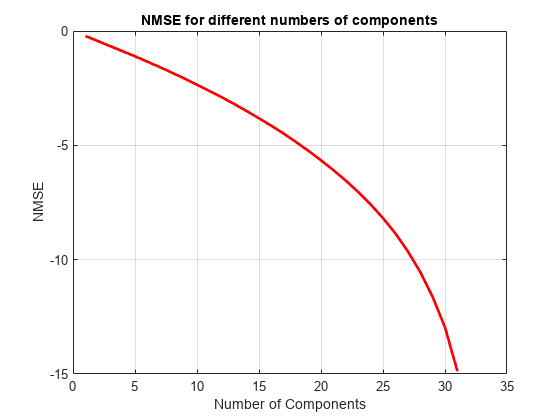

figure;
plot(dims, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

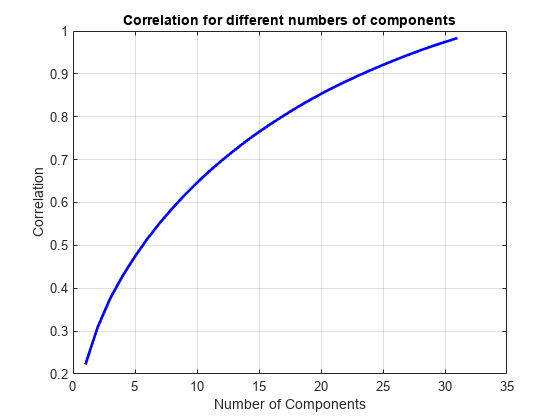

% Построение графика для корреляции
figure;
plot(dims, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;

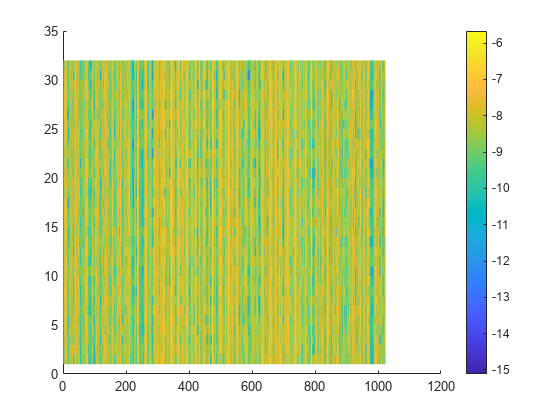


figure; clf; hold on;
B_dft = squeeze(H_dataset(1,1,:,:));
Bt=fft2(B_dft);
Flow = log(abs(fftshift(Bt))); % перевод БПФ в логарифмическую шкалу
surf(Flow, 'EdgeColor', 'none'); colorbar;
view(0,90);

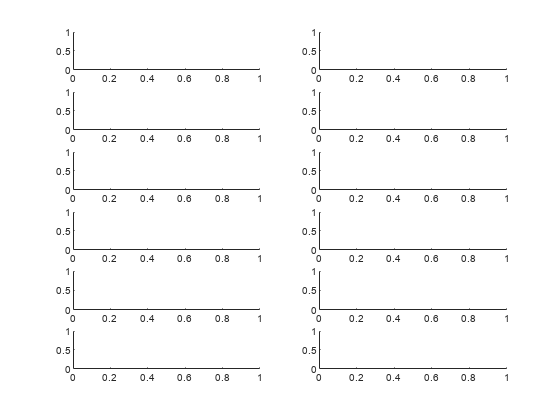

ans = "{99}"

CorrelationValues = 1.0000

NMSEValues = -51.0820

ans = "{80}"

CorrelationValues = 0.9981

NMSEValues = -24.1937

ans = "{70}"

CorrelationValues = 0.9950

NMSEValues = -20.0527

ans = "{60}"

CorrelationValues = 0.9896

NMSEValues = -16.8427

ans = "{50}"

CorrelationValues = 0.9803

NMSEValues = -14.0896

ans = "{40}"

CorrelationValues = 0.9642

NMSEValues = -11.5329

ans = "{30}"

CorrelationValues = 0.9354

NMSEValues = -9.0284

ans = "{20}"

CorrelationValues = 0.8805

NMSEValues = -6.4829

ans = "{10}"

CorrelationValues = 0.7693

NMSEValues = -3.8908

ans = "{5}"

CorrelationValues = 0.6503

NMSEValues = -2.3876

ans = "{1}"

CorrelationValues = 0.4006

NMSEValues = -0.7599

ans = "{5.000000e-01}"

CorrelationValues = 0.3137

NMSEValues = -0.4498


% Обнуление всех малых коэффициентов и обратное преобразование

Btsort = sort(abs(Bt(:))); % Сортировка по величине

figure; clf; hold on;

keep = [.99 .80 .70 .60 .50 .40 .30 .20 .10 .05 .01 .005];

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(keep));
hNMSEValues = zeros(size(keep));

for i = 1:length(keep)
    k = keep(i);
    subplot(length(keep)/2,2,i);
    thresh = Btsort(floor((1-k)*length(Btsort)));
    ind = abs(Bt)>thresh; % Find small indices
    Atlow = Bt.*ind; % Threshold small indices
    
    Alow=ifft2(Atlow); % Compressed image
%     surf(10*log10(abs(Atlow)), 'EdgeColor', 'none'); colorbar;
%     surf(abs(Alow), 'EdgeColor', 'none'); colorbar;
%     view(0,90);
%     title(sprintf("{%d}", k*100));
    sprintf("{%d}", k*100)
    CorrelationValues = hCorrelation(B_dft, Alow)
    NMSEValues = hNMSE(B_dft, Alow)
    % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
end

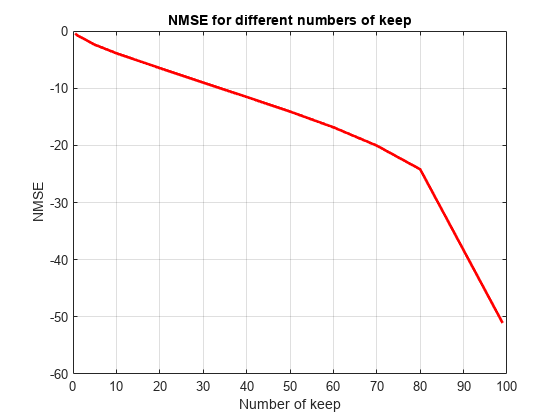


% Построение графика для NMSE
figure;
plot(keep * 100, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of keep');
ylabel('NMSE');
title('NMSE for different numbers of keep');
grid on;

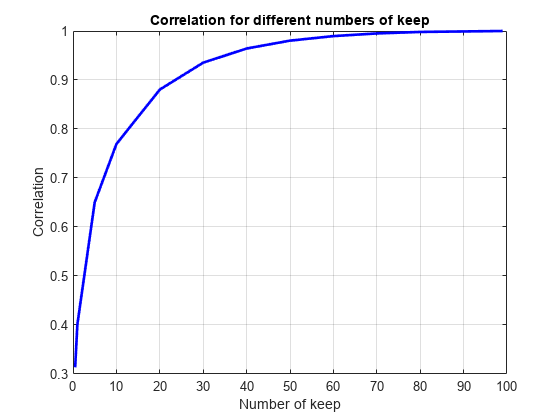

% Построение графика для корреляции
figure;
plot(keep * 100, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of keep');
ylabel('Correlation');
title('Correlation for different numbers of keep');
grid on;

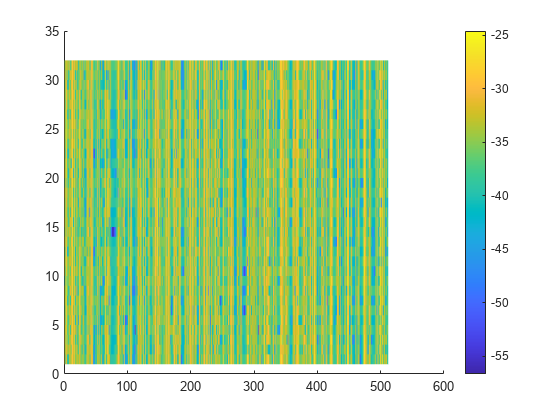

figure; clf; hold on;
surf(10*log10(abs(squeeze(Htemp(:,:)))), 'EdgeColor', 'none'); colorbar;

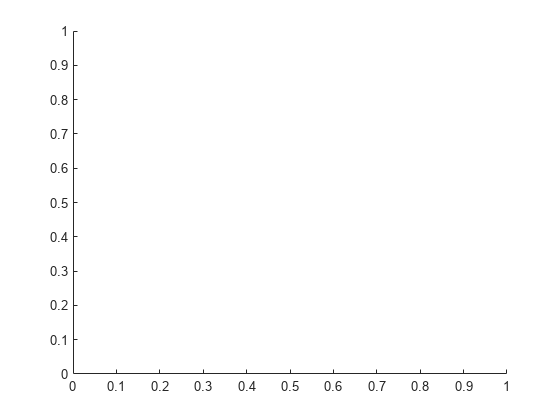

figure; clf; hold on;

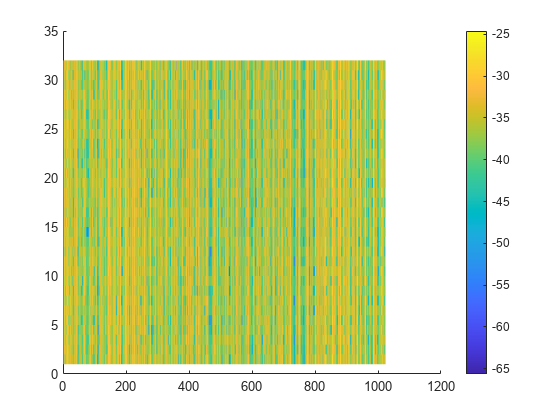


% Подсчитываем Евклидову норму и сортируем строки
% k = 10;
% norms_sum = squeeze(sum(power(abs(Bt),2),1));
% [sorted_norms,sorted_index] = sort(norms_sum);
% select_index = sort(sorted_index(1:k));
% 
% % Создание новой матрицы H_ex
% H_ex = Bt(:,select_index);
% 
% % Создание вектора нулей и установка нужных элементов в 1
% zero_vector = zeros(1, size(Bt, 2));
% zero_vector(select_index) = 1;


B_dft = squeeze(H_dataset(1,1,:,:));
Bt=fft2(B_dft);
figure; clf; hold on;
surf(10*log10(abs(squeeze(Bt))), 'EdgeColor', 'none'); colorbar;

keep = 2:1:size(Bt, 2);

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(keep));
hNMSEValues = zeros(size(keep));

for i = 1:length(keep)
    k = keep(i);

%     norms_sum = squeeze(sum(power(abs(Bt(:,:)),2),1));
    norms_sum = sum(abs(Bt(:,:)),1);
    [sorted_norms,sorted_index] = sort(norms_sum, "descend");
%     select_index = sort(sorted_index(1:k));
    select_index = sort(sorted_index(1:k));
    % Создание новой матрицы c пороговым значением и её усечение
    Atlow = Bt(:,select_index);
%     figure; clf; hold on;
%     surf(10*log10(abs(squeeze(Atlow))), 'EdgeColor', 'none'); colorbar;

    % Создание вектора нулей и установка нужных элементов в 1
    zero_vector = zeros(1, size(Bt, 2));
    zero_vector(select_index) = 1;
    
    % Создаем восстановленную матрицу с нулями
    reconstructed_Bt = zeros(size(Bt));
    % Отмечаем строки, которые нужно заполнить значениями из Atlow
    fill_rows = zero_vector == 1; 
    
    % Заполнение строк матрицы reconstructed_Bt с использованием булевых условий
    reconstructed_Bt(:,fill_rows) = Atlow(:,:);

    Alow=ifft2(reconstructed_Bt); % Compressed image

    CorrelationValues = hCorrelation(B_dft, Alow)
    NMSEValues = hNMSE(B_dft, Alow)
    % Сохранение значений метрик
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
end

CorrelationValues = 0.1865

NMSEValues = -0.1537

CorrelationValues = 0.2257

NMSEValues = -0.2271

CorrelationValues = 0.2565

NMSEValues = -0.2955

CorrelationValues = 0.2833

NMSEValues = -0.3633

CorrelationValues = 0.3059

NMSEValues = -0.4266

CorrelationValues = 0.3245

NMSEValues = -0.4833

CorrelationValues = 0.3407

NMSEValues = -0.5359

CorrelationValues = 0.3535

NMSEValues = -0.5797

CorrelationValues = 0.3659

NMSEValues = -0.6243

CorrelationValues = 0.3775

NMSEValues = -0.6677

CorrelationValues = 0.3880

NMSEValues = -0.7084

CorrelationValues = 0.3989

NMSEValues = -0.7526

CorrelationValues = 0.4092

NMSEValues = -0.7959

CorrelationValues = 0.4177

NMSEValues = -0.8326

CorrelationValues = 0.4267

NMSEValues = -0.8728

CorrelationValues = 0.4346

NMSEValues = -0.9090

CorrelationValues = 0.4438

NMSEValues = -0.9524

CorrelationValues = 0.4518

NMSEValues = -0.9916

CorrelationValues = 0.4590

NMSEValues = -1.0276

CorrelationValues = 0.4663

NMSEValues = -1.0650

CorrelationValues = 0.4737

NMSEValues = -1.1036

CorrelationValues = 0.4802

NMSEValues = -1.1385

CorrelationValues = 0.4877

NMSEValues = -1.1799

CorrelationValues = 0.4941

NMSEValues = -1.2156

CorrelationValues = 0.5005

NMSEValues = -1.2524

CorrelationValues = 0.5064

NMSEValues = -1.2870

CorrelationValues = 0.5122

NMSEValues = -1.3217

CorrelationValues = 0.5185

NMSEValues = -1.3599

CorrelationValues = 0.5243

NMSEValues = -1.3958

CorrelationValues = 0.5303

NMSEValues = -1.4340

CorrelationValues = 0.5359

NMSEValues = -1.4700

CorrelationValues = 0.5414

NMSEValues = -1.5066

CorrelationValues = 0.5469

NMSEValues = -1.5435

CorrelationValues = 0.5521

NMSEValues = -1.5793

CorrelationValues = 0.5572

NMSEValues = -1.6144

CorrelationValues = 0.5620

NMSEValues = -1.6482

CorrelationValues = 0.5669

NMSEValues = -1.6835

CorrelationValues = 0.5724

NMSEValues = -1.7238

CorrelationValues = 0.5768

NMSEValues = -1.7571

CorrelationValues = 0.5812

NMSEValues = -1.7903

CorrelationValues = 0.5858

NMSEValues = -1.8257

CorrelationValues = 0.5900

NMSEValues = -1.8583

CorrelationValues = 0.5941

NMSEValues = -1.8904

CorrelationValues = 0.5980

NMSEValues = -1.9223

CorrelationValues = 0.6026

NMSEValues = -1.9593

CorrelationValues = 0.6069

NMSEValues = -1.9949

CorrelationValues = 0.6107

NMSEValues = -2.0272

CorrelationValues = 0.6145

NMSEValues = -2.0591

CorrelationValues = 0.6183

NMSEValues = -2.0918

CorrelationValues = 0.6219

NMSEValues = -2.1237

CorrelationValues = 0.6253

NMSEValues = -2.1541

CorrelationValues = 0.6286

NMSEValues = -2.1837

CorrelationValues = 0.6325

NMSEValues = -2.2185

CorrelationValues = 0.6359

NMSEValues = -2.2505

CorrelationValues = 0.6389

NMSEValues = -2.2779

CorrelationValues = 0.6419

NMSEValues = -2.3069

CorrelationValues = 0.6447

NMSEValues = -2.3334

CorrelationValues = 0.6476

NMSEValues = -2.3615

CorrelationValues = 0.6508

NMSEValues = -2.3925

CorrelationValues = 0.6535

NMSEValues = -2.4191

CorrelationValues = 0.6562

NMSEValues = -2.4456

CorrelationValues = 0.6590

NMSEValues = -2.4735

CorrelationValues = 0.6616

NMSEValues = -2.5006

CorrelationValues = 0.6642

NMSEValues = -2.5270

CorrelationValues = 0.6670

NMSEValues = -2.5559

CorrelationValues = 0.6699

NMSEValues = -2.5867

CorrelationValues = 0.6726

NMSEValues = -2.6156

CorrelationValues = 0.6751

NMSEValues = -2.6418

CorrelationValues = 0.6781

NMSEValues = -2.6742

CorrelationValues = 0.6805

NMSEValues = -2.7008

CorrelationValues = 0.6833

NMSEValues = -2.7319

CorrelationValues = 0.6856

NMSEValues = -2.7580

CorrelationValues = 0.6879

NMSEValues = -2.7835

CorrelationValues = 0.6901

NMSEValues = -2.8082

CorrelationValues = 0.6922

NMSEValues = -2.8327

CorrelationValues = 0.6944

NMSEValues = -2.8578

CorrelationValues = 0.6967

NMSEValues = -2.8853

CorrelationValues = 0.6991

NMSEValues = -2.9137

CorrelationValues = 0.7017

NMSEValues = -2.9444

CorrelationValues = 0.7039

NMSEValues = -2.9707

CorrelationValues = 0.7059

NMSEValues = -2.9950

CorrelationValues = 0.7077

NMSEValues = -3.0178

CorrelationValues = 0.7099

NMSEValues = -3.0449

CorrelationValues = 0.7117

NMSEValues = -3.0676

CorrelationValues = 0.7137

NMSEValues = -3.0918

CorrelationValues = 0.7155

NMSEValues = -3.1149

CorrelationValues = 0.7173

NMSEValues = -3.1379

CorrelationValues = 0.7191

NMSEValues = -3.1609

CorrelationValues = 0.7210

NMSEValues = -3.1867

CorrelationValues = 0.7227

NMSEValues = -3.2088

CorrelationValues = 0.7247

NMSEValues = -3.2351

CorrelationValues = 0.7268

NMSEValues = -3.2624

CorrelationValues = 0.7286

NMSEValues = -3.2870

CorrelationValues = 0.7303

NMSEValues = -3.3104

CorrelationValues = 0.7320

NMSEValues = -3.3327

CorrelationValues = 0.7336

NMSEValues = -3.3557

CorrelationValues = 0.7355

NMSEValues = -3.3811

CorrelationValues = 0.7370

NMSEValues = -3.4026

CorrelationValues = 0.7387

NMSEValues = -3.4258

CorrelationValues = 0.7402

NMSEValues = -3.4475

CorrelationValues = 0.7418

NMSEValues = -3.4711

CorrelationValues = 0.7433

NMSEValues = -3.4925

CorrelationValues = 0.7449

NMSEValues = -3.5148

CorrelationValues = 0.7463

NMSEValues = -3.5360

CorrelationValues = 0.7478

NMSEValues = -3.5576

CorrelationValues = 0.7494

NMSEValues = -3.5815

CorrelationValues = 0.7509

NMSEValues = -3.6032

CorrelationValues = 0.7523

NMSEValues = -3.6253

CorrelationValues = 0.7538

NMSEValues = -3.6476

CorrelationValues = 0.7552

NMSEValues = -3.6684

CorrelationValues = 0.7566

NMSEValues = -3.6897

CorrelationValues = 0.7580

NMSEValues = -3.7109

CorrelationValues = 0.7595

NMSEValues = -3.7350

CorrelationValues = 0.7610

NMSEValues = -3.7581

CorrelationValues = 0.7623

NMSEValues = -3.7789

CorrelationValues = 0.7638

NMSEValues = -3.8030

CorrelationValues = 0.7651

NMSEValues = -3.8234

CorrelationValues = 0.7663

NMSEValues = -3.8436

CorrelationValues = 0.7676

NMSEValues = -3.8637

CorrelationValues = 0.7689

NMSEValues = -3.8854

CorrelationValues = 0.7702

NMSEValues = -3.9063

CorrelationValues = 0.7715

NMSEValues = -3.9280

CorrelationValues = 0.7728

NMSEValues = -3.9499

CorrelationValues = 0.7740

NMSEValues = -3.9697

CorrelationValues = 0.7752

NMSEValues = -3.9899

CorrelationValues = 0.7766

NMSEValues = -4.0140

CorrelationValues = 0.7780

NMSEValues = -4.0373

CorrelationValues = 0.7792

NMSEValues = -4.0573

CorrelationValues = 0.7804

NMSEValues = -4.0790

CorrelationValues = 0.7816

NMSEValues = -4.0992

CorrelationValues = 0.7828

NMSEValues = -4.1201

CorrelationValues = 0.7839

NMSEValues = -4.1403

CorrelationValues = 0.7853

NMSEValues = -4.1641

CorrelationValues = 0.7866

NMSEValues = -4.1870

CorrelationValues = 0.7877

NMSEValues = -4.2082

CorrelationValues = 0.7889

NMSEValues = -4.2296

CorrelationValues = 0.7900

NMSEValues = -4.2499

CorrelationValues = 0.7913

NMSEValues = -4.2727

CorrelationValues = 0.7924

NMSEValues = -4.2940

CorrelationValues = 0.7937

NMSEValues = -4.3173

CorrelationValues = 0.7949

NMSEValues = -4.3408

CorrelationValues = 0.7961

NMSEValues = -4.3623

CorrelationValues = 0.7972

NMSEValues = -4.3831

CorrelationValues = 0.7985

NMSEValues = -4.4080

CorrelationValues = 0.7996

NMSEValues = -4.4299

CorrelationValues = 0.8007

NMSEValues = -4.4504

CorrelationValues = 0.8020

NMSEValues = -4.4749

CorrelationValues = 0.8032

NMSEValues = -4.4989

CorrelationValues = 0.8043

NMSEValues = -4.5215

CorrelationValues = 0.8054

NMSEValues = -4.5438

CorrelationValues = 0.8065

NMSEValues = -4.5648

CorrelationValues = 0.8077

NMSEValues = -4.5894

CorrelationValues = 0.8088

NMSEValues = -4.6103

CorrelationValues = 0.8098

NMSEValues = -4.6313

CorrelationValues = 0.8108

NMSEValues = -4.6516

CorrelationValues = 0.8119

NMSEValues = -4.6742

CorrelationValues = 0.8134

NMSEValues = -4.7056

CorrelationValues = 0.8144

NMSEValues = -4.7261

CorrelationValues = 0.8153

NMSEValues = -4.7467

CorrelationValues = 0.8163

NMSEValues = -4.7674

CorrelationValues = 0.8173

NMSEValues = -4.7893

CorrelationValues = 0.8184

NMSEValues = -4.8119

CorrelationValues = 0.8194

NMSEValues = -4.8327

CorrelationValues = 0.8204

NMSEValues = -4.8549

CorrelationValues = 0.8214

NMSEValues = -4.8774

CorrelationValues = 0.8223

NMSEValues = -4.8980

CorrelationValues = 0.8234

NMSEValues = -4.9205

CorrelationValues = 0.8243

NMSEValues = -4.9417

CorrelationValues = 0.8253

NMSEValues = -4.9632

CorrelationValues = 0.8262

NMSEValues = -4.9840

CorrelationValues = 0.8271

NMSEValues = -5.0048

CorrelationValues = 0.8280

NMSEValues = -5.0251

CorrelationValues = 0.8291

NMSEValues = -5.0491

CorrelationValues = 0.8300

NMSEValues = -5.0719

CorrelationValues = 0.8309

NMSEValues = -5.0927

CorrelationValues = 0.8319

NMSEValues = -5.1148

CorrelationValues = 0.8328

NMSEValues = -5.1357

CorrelationValues = 0.8337

NMSEValues = -5.1582

CorrelationValues = 0.8346

NMSEValues = -5.1789

CorrelationValues = 0.8355

NMSEValues = -5.2013

CorrelationValues = 0.8364

NMSEValues = -5.2223

CorrelationValues = 0.8372

NMSEValues = -5.2431

CorrelationValues = 0.8382

NMSEValues = -5.2652

CorrelationValues = 0.8391

NMSEValues = -5.2883

CorrelationValues = 0.8399

NMSEValues = -5.3093

CorrelationValues = 0.8408

NMSEValues = -5.3311

CorrelationValues = 0.8417

NMSEValues = -5.3518

CorrelationValues = 0.8427

NMSEValues = -5.3783

CorrelationValues = 0.8436

NMSEValues = -5.4001

CorrelationValues = 0.8444

NMSEValues = -5.4217

CorrelationValues = 0.8454

NMSEValues = -5.4460

CorrelationValues = 0.8462

NMSEValues = -5.4681

CorrelationValues = 0.8471

NMSEValues = -5.4911

CorrelationValues = 0.8479

NMSEValues = -5.5128

CorrelationValues = 0.8489

NMSEValues = -5.5371

CorrelationValues = 0.8497

NMSEValues = -5.5600

CorrelationValues = 0.8505

NMSEValues = -5.5813

CorrelationValues = 0.8515

NMSEValues = -5.6065

CorrelationValues = 0.8523

NMSEValues = -5.6284

CorrelationValues = 0.8531

NMSEValues = -5.6497

CorrelationValues = 0.8540

NMSEValues = -5.6746

CorrelationValues = 0.8549

NMSEValues = -5.7001

CorrelationValues = 0.8557

NMSEValues = -5.7216

CorrelationValues = 0.8565

NMSEValues = -5.7432

CorrelationValues = 0.8572

NMSEValues = -5.7655

CorrelationValues = 0.8582

NMSEValues = -5.7918

CorrelationValues = 0.8590

NMSEValues = -5.8151

CorrelationValues = 0.8598

NMSEValues = -5.8369

CorrelationValues = 0.8607

NMSEValues = -5.8632

CorrelationValues = 0.8615

NMSEValues = -5.8855

CorrelationValues = 0.8623

NMSEValues = -5.9110

CorrelationValues = 0.8632

NMSEValues = -5.9359

CorrelationValues = 0.8641

NMSEValues = -5.9622

CorrelationValues = 0.8648

NMSEValues = -5.9844

CorrelationValues = 0.8657

NMSEValues = -6.0099

CorrelationValues = 0.8664

NMSEValues = -6.0316

CorrelationValues = 0.8671

NMSEValues = -6.0538

CorrelationValues = 0.8678

NMSEValues = -6.0755

CorrelationValues = 0.8686

NMSEValues = -6.0978

CorrelationValues = 0.8693

NMSEValues = -6.1201

CorrelationValues = 0.8701

NMSEValues = -6.1464

CorrelationValues = 0.8709

NMSEValues = -6.1706

CorrelationValues = 0.8716

NMSEValues = -6.1928

CorrelationValues = 0.8723

NMSEValues = -6.2144

CorrelationValues = 0.8731

NMSEValues = -6.2383

CorrelationValues = 0.8737

NMSEValues = -6.2603

CorrelationValues = 0.8744

NMSEValues = -6.2819

CorrelationValues = 0.8751

NMSEValues = -6.3036

CorrelationValues = 0.8759

NMSEValues = -6.3288

CorrelationValues = 0.8766

NMSEValues = -6.3516

CorrelationValues = 0.8772

NMSEValues = -6.3727

CorrelationValues = 0.8779

NMSEValues = -6.3962

CorrelationValues = 0.8785

NMSEValues = -6.4176

CorrelationValues = 0.8792

NMSEValues = -6.4411

CorrelationValues = 0.8799

NMSEValues = -6.4625

CorrelationValues = 0.8806

NMSEValues = -6.4855

CorrelationValues = 0.8812

NMSEValues = -6.5073

CorrelationValues = 0.8819

NMSEValues = -6.5321

CorrelationValues = 0.8826

NMSEValues = -6.5560

CorrelationValues = 0.8833

NMSEValues = -6.5804

CorrelationValues = 0.8839

NMSEValues = -6.6028

CorrelationValues = 0.8845

NMSEValues = -6.6237

CorrelationValues = 0.8851

NMSEValues = -6.6446

CorrelationValues = 0.8857

NMSEValues = -6.6660

CorrelationValues = 0.8863

NMSEValues = -6.6881

CorrelationValues = 0.8870

NMSEValues = -6.7127

CorrelationValues = 0.8877

NMSEValues = -6.7384

CorrelationValues = 0.8883

NMSEValues = -6.7596

CorrelationValues = 0.8889

NMSEValues = -6.7811

CorrelationValues = 0.8896

NMSEValues = -6.8071

CorrelationValues = 0.8902

NMSEValues = -6.8291

CorrelationValues = 0.8908

NMSEValues = -6.8512

CorrelationValues = 0.8914

NMSEValues = -6.8744

CorrelationValues = 0.8920

NMSEValues = -6.8969

CorrelationValues = 0.8926

NMSEValues = -6.9191

CorrelationValues = 0.8932

NMSEValues = -6.9407

CorrelationValues = 0.8937

NMSEValues = -6.9631

CorrelationValues = 0.8944

NMSEValues = -6.9881

CorrelationValues = 0.8950

NMSEValues = -7.0118

CorrelationValues = 0.8955

NMSEValues = -7.0334

CorrelationValues = 0.8961

NMSEValues = -7.0560

CorrelationValues = 0.8967

NMSEValues = -7.0777

CorrelationValues = 0.8973

NMSEValues = -7.1017

CorrelationValues = 0.8979

NMSEValues = -7.1261

CorrelationValues = 0.8986

NMSEValues = -7.1536

CorrelationValues = 0.8991

NMSEValues = -7.1762

CorrelationValues = 0.8996

NMSEValues = -7.1981

CorrelationValues = 0.9002

NMSEValues = -7.2200

CorrelationValues = 0.9008

NMSEValues = -7.2448

CorrelationValues = 0.9014

NMSEValues = -7.2712

CorrelationValues = 0.9020

NMSEValues = -7.2944

CorrelationValues = 0.9025

NMSEValues = -7.3176

CorrelationValues = 0.9031

NMSEValues = -7.3434

CorrelationValues = 0.9036

NMSEValues = -7.3654

CorrelationValues = 0.9042

NMSEValues = -7.3913

CorrelationValues = 0.9048

NMSEValues = -7.4139

CorrelationValues = 0.9053

NMSEValues = -7.4373

CorrelationValues = 0.9058

NMSEValues = -7.4594

CorrelationValues = 0.9064

NMSEValues = -7.4838

CorrelationValues = 0.9070

NMSEValues = -7.5097

CorrelationValues = 0.9074

NMSEValues = -7.5315

CorrelationValues = 0.9080

NMSEValues = -7.5548

CorrelationValues = 0.9085

NMSEValues = -7.5769

CorrelationValues = 0.9090

NMSEValues = -7.5996

CorrelationValues = 0.9095

NMSEValues = -7.6229

CorrelationValues = 0.9100

NMSEValues = -7.6456

CorrelationValues = 0.9105

NMSEValues = -7.6686

CorrelationValues = 0.9109

NMSEValues = -7.6909

CorrelationValues = 0.9115

NMSEValues = -7.7156

CorrelationValues = 0.9120

NMSEValues = -7.7390

CorrelationValues = 0.9124

NMSEValues = -7.7610

CorrelationValues = 0.9129

NMSEValues = -7.7835

CorrelationValues = 0.9134

NMSEValues = -7.8066

CorrelationValues = 0.9139

NMSEValues = -7.8296

CorrelationValues = 0.9144

NMSEValues = -7.8560

CorrelationValues = 0.9149

NMSEValues = -7.8790

CorrelationValues = 0.9154

NMSEValues = -7.9014

CorrelationValues = 0.9159

NMSEValues = -7.9263

CorrelationValues = 0.9164

NMSEValues = -7.9525

CorrelationValues = 0.9168

NMSEValues = -7.9754

CorrelationValues = 0.9173

NMSEValues = -7.9977

CorrelationValues = 0.9178

NMSEValues = -8.0229

CorrelationValues = 0.9183

NMSEValues = -8.0475

CorrelationValues = 0.9187

NMSEValues = -8.0703

CorrelationValues = 0.9192

NMSEValues = -8.0952

CorrelationValues = 0.9197

NMSEValues = -8.1197

CorrelationValues = 0.9201

NMSEValues = -8.1438

CorrelationValues = 0.9206

NMSEValues = -8.1699

CorrelationValues = 0.9211

NMSEValues = -8.1959

CorrelationValues = 0.9216

NMSEValues = -8.2191

CorrelationValues = 0.9220

NMSEValues = -8.2429

CorrelationValues = 0.9225

NMSEValues = -8.2666

CorrelationValues = 0.9229

NMSEValues = -8.2901

CorrelationValues = 0.9234

NMSEValues = -8.3167

CorrelationValues = 0.9238

NMSEValues = -8.3395

CorrelationValues = 0.9243

NMSEValues = -8.3650

CorrelationValues = 0.9248

NMSEValues = -8.3913

CorrelationValues = 0.9252

NMSEValues = -8.4162

CorrelationValues = 0.9256

NMSEValues = -8.4401

CorrelationValues = 0.9261

NMSEValues = -8.4659

CorrelationValues = 0.9265

NMSEValues = -8.4898

CorrelationValues = 0.9270

NMSEValues = -8.5157

CorrelationValues = 0.9273

NMSEValues = -8.5377

CorrelationValues = 0.9278

NMSEValues = -8.5624

CorrelationValues = 0.9281

NMSEValues = -8.5842

CorrelationValues = 0.9285

NMSEValues = -8.6057

CorrelationValues = 0.9289

NMSEValues = -8.6311

CorrelationValues = 0.9293

NMSEValues = -8.6534

CorrelationValues = 0.9297

NMSEValues = -8.6764

CorrelationValues = 0.9301

NMSEValues = -8.7012

CorrelationValues = 0.9305

NMSEValues = -8.7248

CorrelationValues = 0.9309

NMSEValues = -8.7459

CorrelationValues = 0.9312

NMSEValues = -8.7668

CorrelationValues = 0.9316

NMSEValues = -8.7918

CorrelationValues = 0.9320

NMSEValues = -8.8131

CorrelationValues = 0.9324

NMSEValues = -8.8384

CorrelationValues = 0.9327

NMSEValues = -8.8604

CorrelationValues = 0.9331

NMSEValues = -8.8853

CorrelationValues = 0.9335

NMSEValues = -8.9078

CorrelationValues = 0.9338

NMSEValues = -8.9287

CorrelationValues = 0.9342

NMSEValues = -8.9522

CorrelationValues = 0.9346

NMSEValues = -8.9759

CorrelationValues = 0.9349

NMSEValues = -8.9979

CorrelationValues = 0.9352

NMSEValues = -9.0195

CorrelationValues = 0.9356

NMSEValues = -9.0407

CorrelationValues = 0.9359

NMSEValues = -9.0642

CorrelationValues = 0.9363

NMSEValues = -9.0867

CorrelationValues = 0.9366

NMSEValues = -9.1119

CorrelationValues = 0.9370

NMSEValues = -9.1332

CorrelationValues = 0.9373

NMSEValues = -9.1565

CorrelationValues = 0.9376

NMSEValues = -9.1784

CorrelationValues = 0.9380

NMSEValues = -9.2018

CorrelationValues = 0.9383

NMSEValues = -9.2251

CorrelationValues = 0.9386

NMSEValues = -9.2455

CorrelationValues = 0.9389

NMSEValues = -9.2671

CorrelationValues = 0.9393

NMSEValues = -9.2883

CorrelationValues = 0.9396

NMSEValues = -9.3091

CorrelationValues = 0.9399

NMSEValues = -9.3311

CorrelationValues = 0.9402

NMSEValues = -9.3524

CorrelationValues = 0.9405

NMSEValues = -9.3738

CorrelationValues = 0.9408

NMSEValues = -9.3976

CorrelationValues = 0.9411

NMSEValues = -9.4216

CorrelationValues = 0.9415

NMSEValues = -9.4439

CorrelationValues = 0.9418

NMSEValues = -9.4665

CorrelationValues = 0.9421

NMSEValues = -9.4895

CorrelationValues = 0.9424

NMSEValues = -9.5105

CorrelationValues = 0.9427

NMSEValues = -9.5317

CorrelationValues = 0.9430

NMSEValues = -9.5546

CorrelationValues = 0.9433

NMSEValues = -9.5779

CorrelationValues = 0.9436

NMSEValues = -9.5981

CorrelationValues = 0.9438

NMSEValues = -9.6189

CorrelationValues = 0.9441

NMSEValues = -9.6407

CorrelationValues = 0.9445

NMSEValues = -9.6664

CorrelationValues = 0.9448

NMSEValues = -9.6903

CorrelationValues = 0.9451

NMSEValues = -9.7134

CorrelationValues = 0.9454

NMSEValues = -9.7373

CorrelationValues = 0.9457

NMSEValues = -9.7628

CorrelationValues = 0.9460

NMSEValues = -9.7850

CorrelationValues = 0.9463

NMSEValues = -9.8052

CorrelationValues = 0.9466

NMSEValues = -9.8283

CorrelationValues = 0.9469

NMSEValues = -9.8525

CorrelationValues = 0.9471

NMSEValues = -9.8728

CorrelationValues = 0.9474

NMSEValues = -9.8940

CorrelationValues = 0.9476

NMSEValues = -9.9157

CorrelationValues = 0.9479

NMSEValues = -9.9391

CorrelationValues = 0.9482

NMSEValues = -9.9596

CorrelationValues = 0.9484

NMSEValues = -9.9802

CorrelationValues = 0.9487

NMSEValues = -10.0043

CorrelationValues = 0.9490

NMSEValues = -10.0258

CorrelationValues = 0.9493

NMSEValues = -10.0483

CorrelationValues = 0.9495

NMSEValues = -10.0695

CorrelationValues = 0.9498

NMSEValues = -10.0901

CorrelationValues = 0.9500

NMSEValues = -10.1134

CorrelationValues = 0.9503

NMSEValues = -10.1337

CorrelationValues = 0.9505

NMSEValues = -10.1551

CorrelationValues = 0.9508

NMSEValues = -10.1769

CorrelationValues = 0.9510

NMSEValues = -10.1978

CorrelationValues = 0.9513

NMSEValues = -10.2195

CorrelationValues = 0.9515

NMSEValues = -10.2428

CorrelationValues = 0.9518

NMSEValues = -10.2645

CorrelationValues = 0.9521

NMSEValues = -10.2887

CorrelationValues = 0.9523

NMSEValues = -10.3104

CorrelationValues = 0.9526

NMSEValues = -10.3320

CorrelationValues = 0.9528

NMSEValues = -10.3539

CorrelationValues = 0.9531

NMSEValues = -10.3780

CorrelationValues = 0.9533

NMSEValues = -10.3997

CorrelationValues = 0.9536

NMSEValues = -10.4229

CorrelationValues = 0.9538

NMSEValues = -10.4435

CorrelationValues = 0.9540

NMSEValues = -10.4643

CorrelationValues = 0.9543

NMSEValues = -10.4885

CorrelationValues = 0.9545

NMSEValues = -10.5108

CorrelationValues = 0.9547

NMSEValues = -10.5316

CorrelationValues = 0.9550

NMSEValues = -10.5542

CorrelationValues = 0.9552

NMSEValues = -10.5760

CorrelationValues = 0.9554

NMSEValues = -10.5983

CorrelationValues = 0.9557

NMSEValues = -10.6195

CorrelationValues = 0.9559

NMSEValues = -10.6402

CorrelationValues = 0.9561

NMSEValues = -10.6608

CorrelationValues = 0.9563

NMSEValues = -10.6809

CorrelationValues = 0.9565

NMSEValues = -10.7051

CorrelationValues = 0.9568

NMSEValues = -10.7281

CorrelationValues = 0.9570

NMSEValues = -10.7523

CorrelationValues = 0.9573

NMSEValues = -10.7763

CorrelationValues = 0.9575

NMSEValues = -10.7996

CorrelationValues = 0.9577

NMSEValues = -10.8227

CorrelationValues = 0.9579

NMSEValues = -10.8442

CorrelationValues = 0.9582

NMSEValues = -10.8664

CorrelationValues = 0.9584

NMSEValues = -10.8872

CorrelationValues = 0.9586

NMSEValues = -10.9098

CorrelationValues = 0.9588

NMSEValues = -10.9301

CorrelationValues = 0.9590

NMSEValues = -10.9527

CorrelationValues = 0.9592

NMSEValues = -10.9754

CorrelationValues = 0.9595

NMSEValues = -10.9992

CorrelationValues = 0.9597

NMSEValues = -11.0234

CorrelationValues = 0.9599

NMSEValues = -11.0440

CorrelationValues = 0.9601

NMSEValues = -11.0657

CorrelationValues = 0.9603

NMSEValues = -11.0861

CorrelationValues = 0.9605

NMSEValues = -11.1059

CorrelationValues = 0.9606

NMSEValues = -11.1255

CorrelationValues = 0.9608

NMSEValues = -11.1466

CorrelationValues = 0.9610

NMSEValues = -11.1689

CorrelationValues = 0.9612

NMSEValues = -11.1889

CorrelationValues = 0.9614

NMSEValues = -11.2085

CorrelationValues = 0.9616

NMSEValues = -11.2285

CorrelationValues = 0.9618

NMSEValues = -11.2515

CorrelationValues = 0.9620

NMSEValues = -11.2720

CorrelationValues = 0.9622

NMSEValues = -11.2932

CorrelationValues = 0.9623

NMSEValues = -11.3140

CorrelationValues = 0.9625

NMSEValues = -11.3335

CorrelationValues = 0.9627

NMSEValues = -11.3563

CorrelationValues = 0.9629

NMSEValues = -11.3769

CorrelationValues = 0.9631

NMSEValues = -11.3980

CorrelationValues = 0.9633

NMSEValues = -11.4221

CorrelationValues = 0.9635

NMSEValues = -11.4453

CorrelationValues = 0.9637

NMSEValues = -11.4679

CorrelationValues = 0.9639

NMSEValues = -11.4900

CorrelationValues = 0.9640

NMSEValues = -11.5103

CorrelationValues = 0.9642

NMSEValues = -11.5333

CorrelationValues = 0.9644

NMSEValues = -11.5555

CorrelationValues = 0.9646

NMSEValues = -11.5769

CorrelationValues = 0.9648

NMSEValues = -11.5990

CorrelationValues = 0.9649

NMSEValues = -11.6190

CorrelationValues = 0.9651

NMSEValues = -11.6401

CorrelationValues = 0.9653

NMSEValues = -11.6612

CorrelationValues = 0.9655

NMSEValues = -11.6814

CorrelationValues = 0.9656

NMSEValues = -11.7020

CorrelationValues = 0.9658

NMSEValues = -11.7264

CorrelationValues = 0.9660

NMSEValues = -11.7471

CorrelationValues = 0.9662

NMSEValues = -11.7699

CorrelationValues = 0.9663

NMSEValues = -11.7933

CorrelationValues = 0.9665

NMSEValues = -11.8144

CorrelationValues = 0.9667

NMSEValues = -11.8353

CorrelationValues = 0.9669

NMSEValues = -11.8580

CorrelationValues = 0.9670

NMSEValues = -11.8772

CorrelationValues = 0.9672

NMSEValues = -11.8977

CorrelationValues = 0.9673

NMSEValues = -11.9182

CorrelationValues = 0.9675

NMSEValues = -11.9407

CorrelationValues = 0.9677

NMSEValues = -11.9632

CorrelationValues = 0.9678

NMSEValues = -11.9863

CorrelationValues = 0.9680

NMSEValues = -12.0090

CorrelationValues = 0.9682

NMSEValues = -12.0305

CorrelationValues = 0.9683

NMSEValues = -12.0526

CorrelationValues = 0.9685

NMSEValues = -12.0726

CorrelationValues = 0.9687

NMSEValues = -12.0962

CorrelationValues = 0.9688

NMSEValues = -12.1193

CorrelationValues = 0.9690

NMSEValues = -12.1405

CorrelationValues = 0.9691

NMSEValues = -12.1613

CorrelationValues = 0.9693

NMSEValues = -12.1834

CorrelationValues = 0.9694

NMSEValues = -12.2055

CorrelationValues = 0.9696

NMSEValues = -12.2324

CorrelationValues = 0.9698

NMSEValues = -12.2523

CorrelationValues = 0.9699

NMSEValues = -12.2742

CorrelationValues = 0.9701

NMSEValues = -12.2937

CorrelationValues = 0.9702

NMSEValues = -12.3167

CorrelationValues = 0.9704

NMSEValues = -12.3381

CorrelationValues = 0.9705

NMSEValues = -12.3590

CorrelationValues = 0.9707

NMSEValues = -12.3789

CorrelationValues = 0.9708

NMSEValues = -12.4016

CorrelationValues = 0.9709

NMSEValues = -12.4210

CorrelationValues = 0.9711

NMSEValues = -12.4422

CorrelationValues = 0.9712

NMSEValues = -12.4640

CorrelationValues = 0.9714

NMSEValues = -12.4864

CorrelationValues = 0.9715

NMSEValues = -12.5100

CorrelationValues = 0.9717

NMSEValues = -12.5315

CorrelationValues = 0.9718

NMSEValues = -12.5526

CorrelationValues = 0.9720

NMSEValues = -12.5735

CorrelationValues = 0.9721

NMSEValues = -12.5942

CorrelationValues = 0.9722

NMSEValues = -12.6169

CorrelationValues = 0.9724

NMSEValues = -12.6363

CorrelationValues = 0.9725

NMSEValues = -12.6555

CorrelationValues = 0.9726

NMSEValues = -12.6758

CorrelationValues = 0.9727

NMSEValues = -12.6955

CorrelationValues = 0.9729

NMSEValues = -12.7159

CorrelationValues = 0.9730

NMSEValues = -12.7378

CorrelationValues = 0.9731

NMSEValues = -12.7570

CorrelationValues = 0.9733

NMSEValues = -12.7777

CorrelationValues = 0.9734

NMSEValues = -12.7995

CorrelationValues = 0.9735

NMSEValues = -12.8211

CorrelationValues = 0.9737

NMSEValues = -12.8433

CorrelationValues = 0.9738

NMSEValues = -12.8654

CorrelationValues = 0.9739

NMSEValues = -12.8864

CorrelationValues = 0.9741

NMSEValues = -12.9065

CorrelationValues = 0.9742

NMSEValues = -12.9271

CorrelationValues = 0.9743

NMSEValues = -12.9497

CorrelationValues = 0.9744

NMSEValues = -12.9695

CorrelationValues = 0.9746

NMSEValues = -12.9909

CorrelationValues = 0.9747

NMSEValues = -13.0126

CorrelationValues = 0.9748

NMSEValues = -13.0344

CorrelationValues = 0.9749

NMSEValues = -13.0538

CorrelationValues = 0.9751

NMSEValues = -13.0750

CorrelationValues = 0.9752

NMSEValues = -13.0948

CorrelationValues = 0.9753

NMSEValues = -13.1149

CorrelationValues = 0.9754

NMSEValues = -13.1362

CorrelationValues = 0.9756

NMSEValues = -13.1606

CorrelationValues = 0.9757

NMSEValues = -13.1824

CorrelationValues = 0.9758

NMSEValues = -13.2049

CorrelationValues = 0.9759

NMSEValues = -13.2247

CorrelationValues = 0.9760

NMSEValues = -13.2446

CorrelationValues = 0.9762

NMSEValues = -13.2676

CorrelationValues = 0.9763

NMSEValues = -13.2878

CorrelationValues = 0.9764

NMSEValues = -13.3124

CorrelationValues = 0.9765

NMSEValues = -13.3342

CorrelationValues = 0.9766

NMSEValues = -13.3574

CorrelationValues = 0.9768

NMSEValues = -13.3792

CorrelationValues = 0.9769

NMSEValues = -13.4016

CorrelationValues = 0.9770

NMSEValues = -13.4221

CorrelationValues = 0.9771

NMSEValues = -13.4438

CorrelationValues = 0.9772

NMSEValues = -13.4652

CorrelationValues = 0.9773

NMSEValues = -13.4862

CorrelationValues = 0.9775

NMSEValues = -13.5097

CorrelationValues = 0.9776

NMSEValues = -13.5329

CorrelationValues = 0.9777

NMSEValues = -13.5543

CorrelationValues = 0.9778

NMSEValues = -13.5758

CorrelationValues = 0.9779

NMSEValues = -13.5974

CorrelationValues = 0.9780

NMSEValues = -13.6179

CorrelationValues = 0.9781

NMSEValues = -13.6401

CorrelationValues = 0.9782

NMSEValues = -13.6611

CorrelationValues = 0.9783

NMSEValues = -13.6820

CorrelationValues = 0.9785

NMSEValues = -13.7031

CorrelationValues = 0.9786

NMSEValues = -13.7260

CorrelationValues = 0.9787

NMSEValues = -13.7498

CorrelationValues = 0.9788

NMSEValues = -13.7733

CorrelationValues = 0.9789

NMSEValues = -13.7983

CorrelationValues = 0.9790

NMSEValues = -13.8223

CorrelationValues = 0.9792

NMSEValues = -13.8445

CorrelationValues = 0.9793

NMSEValues = -13.8658

CorrelationValues = 0.9794

NMSEValues = -13.8901

CorrelationValues = 0.9795

NMSEValues = -13.9121

CorrelationValues = 0.9796

NMSEValues = -13.9357

CorrelationValues = 0.9797

NMSEValues = -13.9604

CorrelationValues = 0.9798

NMSEValues = -13.9835

CorrelationValues = 0.9799

NMSEValues = -14.0053

CorrelationValues = 0.9800

NMSEValues = -14.0299

CorrelationValues = 0.9801

NMSEValues = -14.0521

CorrelationValues = 0.9802

NMSEValues = -14.0771

CorrelationValues = 0.9804

NMSEValues = -14.1014

CorrelationValues = 0.9805

NMSEValues = -14.1240

CorrelationValues = 0.9806

NMSEValues = -14.1485

CorrelationValues = 0.9807

NMSEValues = -14.1726

CorrelationValues = 0.9808

NMSEValues = -14.1950

CorrelationValues = 0.9809

NMSEValues = -14.2182

CorrelationValues = 0.9810

NMSEValues = -14.2412

CorrelationValues = 0.9811

NMSEValues = -14.2645

CorrelationValues = 0.9812

NMSEValues = -14.2908

CorrelationValues = 0.9813

NMSEValues = -14.3165

CorrelationValues = 0.9814

NMSEValues = -14.3395

CorrelationValues = 0.9815

NMSEValues = -14.3607

CorrelationValues = 0.9816

NMSEValues = -14.3814

CorrelationValues = 0.9817

NMSEValues = -14.4039

CorrelationValues = 0.9818

NMSEValues = -14.4254

CorrelationValues = 0.9819

NMSEValues = -14.4470

CorrelationValues = 0.9820

NMSEValues = -14.4711

CorrelationValues = 0.9821

NMSEValues = -14.4953

CorrelationValues = 0.9822

NMSEValues = -14.5180

CorrelationValues = 0.9823

NMSEValues = -14.5419

CorrelationValues = 0.9824

NMSEValues = -14.5659

CorrelationValues = 0.9825

NMSEValues = -14.5896

CorrelationValues = 0.9826

NMSEValues = -14.6124

CorrelationValues = 0.9827

NMSEValues = -14.6360

CorrelationValues = 0.9827

NMSEValues = -14.6573

CorrelationValues = 0.9828

NMSEValues = -14.6818

CorrelationValues = 0.9829

NMSEValues = -14.7047

CorrelationValues = 0.9830

NMSEValues = -14.7281

CorrelationValues = 0.9831

NMSEValues = -14.7554

CorrelationValues = 0.9832

NMSEValues = -14.7787

CorrelationValues = 0.9833

NMSEValues = -14.8006

CorrelationValues = 0.9834

NMSEValues = -14.8226

CorrelationValues = 0.9835

NMSEValues = -14.8449

CorrelationValues = 0.9836

NMSEValues = -14.8673

CorrelationValues = 0.9837

NMSEValues = -14.8907

CorrelationValues = 0.9837

NMSEValues = -14.9132

CorrelationValues = 0.9838

NMSEValues = -14.9362

CorrelationValues = 0.9839

NMSEValues = -14.9590

CorrelationValues = 0.9840

NMSEValues = -14.9849

CorrelationValues = 0.9841

NMSEValues = -15.0071

CorrelationValues = 0.9842

NMSEValues = -15.0314

CorrelationValues = 0.9843

NMSEValues = -15.0534

CorrelationValues = 0.9843

NMSEValues = -15.0779

CorrelationValues = 0.9844

NMSEValues = -15.1028

CorrelationValues = 0.9845

NMSEValues = -15.1256

CorrelationValues = 0.9846

NMSEValues = -15.1491

CorrelationValues = 0.9847

NMSEValues = -15.1746

CorrelationValues = 0.9848

NMSEValues = -15.1976

CorrelationValues = 0.9849

NMSEValues = -15.2213

CorrelationValues = 0.9849

NMSEValues = -15.2460

CorrelationValues = 0.9850

NMSEValues = -15.2705

CorrelationValues = 0.9851

NMSEValues = -15.2926

CorrelationValues = 0.9852

NMSEValues = -15.3177

CorrelationValues = 0.9853

NMSEValues = -15.3417

CorrelationValues = 0.9854

NMSEValues = -15.3658

CorrelationValues = 0.9854

NMSEValues = -15.3897

CorrelationValues = 0.9855

NMSEValues = -15.4135

CorrelationValues = 0.9856

NMSEValues = -15.4376

CorrelationValues = 0.9857

NMSEValues = -15.4635

CorrelationValues = 0.9858

NMSEValues = -15.4867

CorrelationValues = 0.9859

NMSEValues = -15.5142

CorrelationValues = 0.9859

NMSEValues = -15.5384

CorrelationValues = 0.9860

NMSEValues = -15.5643

CorrelationValues = 0.9861

NMSEValues = -15.5871

CorrelationValues = 0.9862

NMSEValues = -15.6121

CorrelationValues = 0.9862

NMSEValues = -15.6362

CorrelationValues = 0.9863

NMSEValues = -15.6606

CorrelationValues = 0.9864

NMSEValues = -15.6838

CorrelationValues = 0.9865

NMSEValues = -15.7060

CorrelationValues = 0.9865

NMSEValues = -15.7300

CorrelationValues = 0.9866

NMSEValues = -15.7544

CorrelationValues = 0.9867

NMSEValues = -15.7787

CorrelationValues = 0.9868

NMSEValues = -15.8041

CorrelationValues = 0.9868

NMSEValues = -15.8288

CorrelationValues = 0.9869

NMSEValues = -15.8531

CorrelationValues = 0.9870

NMSEValues = -15.8785

CorrelationValues = 0.9871

NMSEValues = -15.9047

CorrelationValues = 0.9872

NMSEValues = -15.9299

CorrelationValues = 0.9872

NMSEValues = -15.9556

CorrelationValues = 0.9873

NMSEValues = -15.9793

CorrelationValues = 0.9874

NMSEValues = -16.0045

CorrelationValues = 0.9874

NMSEValues = -16.0283

CorrelationValues = 0.9875

NMSEValues = -16.0545

CorrelationValues = 0.9876

NMSEValues = -16.0800

CorrelationValues = 0.9877

NMSEValues = -16.1056

CorrelationValues = 0.9877

NMSEValues = -16.1302

CorrelationValues = 0.9878

NMSEValues = -16.1577

CorrelationValues = 0.9879

NMSEValues = -16.1843

CorrelationValues = 0.9880

NMSEValues = -16.2106

CorrelationValues = 0.9880

NMSEValues = -16.2388

CorrelationValues = 0.9881

NMSEValues = -16.2638

CorrelationValues = 0.9882

NMSEValues = -16.2927

CorrelationValues = 0.9883

NMSEValues = -16.3174

CorrelationValues = 0.9883

NMSEValues = -16.3435

CorrelationValues = 0.9884

NMSEValues = -16.3707

CorrelationValues = 0.9885

NMSEValues = -16.3969

CorrelationValues = 0.9885

NMSEValues = -16.4217

CorrelationValues = 0.9886

NMSEValues = -16.4455

CorrelationValues = 0.9887

NMSEValues = -16.4697

CorrelationValues = 0.9887

NMSEValues = -16.4974

CorrelationValues = 0.9888

NMSEValues = -16.5220

CorrelationValues = 0.9889

NMSEValues = -16.5484

CorrelationValues = 0.9889

NMSEValues = -16.5759

CorrelationValues = 0.9890

NMSEValues = -16.6013

CorrelationValues = 0.9891

NMSEValues = -16.6274

CorrelationValues = 0.9891

NMSEValues = -16.6535

CorrelationValues = 0.9892

NMSEValues = -16.6784

CorrelationValues = 0.9893

NMSEValues = -16.7042

CorrelationValues = 0.9893

NMSEValues = -16.7297

CorrelationValues = 0.9894

NMSEValues = -16.7553

CorrelationValues = 0.9895

NMSEValues = -16.7841

CorrelationValues = 0.9895

NMSEValues = -16.8108

CorrelationValues = 0.9896

NMSEValues = -16.8353

CorrelationValues = 0.9896

NMSEValues = -16.8619

CorrelationValues = 0.9897

NMSEValues = -16.8873

CorrelationValues = 0.9898

NMSEValues = -16.9153

CorrelationValues = 0.9898

NMSEValues = -16.9423

CorrelationValues = 0.9899

NMSEValues = -16.9688

CorrelationValues = 0.9900

NMSEValues = -16.9960

CorrelationValues = 0.9900

NMSEValues = -17.0232

CorrelationValues = 0.9901

NMSEValues = -17.0507

CorrelationValues = 0.9902

NMSEValues = -17.0768

CorrelationValues = 0.9902

NMSEValues = -17.1043

CorrelationValues = 0.9903

NMSEValues = -17.1322

CorrelationValues = 0.9903

NMSEValues = -17.1620

CorrelationValues = 0.9904

NMSEValues = -17.1893

CorrelationValues = 0.9905

NMSEValues = -17.2168

CorrelationValues = 0.9905

NMSEValues = -17.2453

CorrelationValues = 0.9906

NMSEValues = -17.2705

CorrelationValues = 0.9906

NMSEValues = -17.2970

CorrelationValues = 0.9907

NMSEValues = -17.3220

CorrelationValues = 0.9907

NMSEValues = -17.3476

CorrelationValues = 0.9908

NMSEValues = -17.3752

CorrelationValues = 0.9909

NMSEValues = -17.4038

CorrelationValues = 0.9909

NMSEValues = -17.4309

CorrelationValues = 0.9910

NMSEValues = -17.4578

CorrelationValues = 0.9910

NMSEValues = -17.4839

CorrelationValues = 0.9911

NMSEValues = -17.5093

CorrelationValues = 0.9911

NMSEValues = -17.5362

CorrelationValues = 0.9912

NMSEValues = -17.5631

CorrelationValues = 0.9913

NMSEValues = -17.5895

CorrelationValues = 0.9913

NMSEValues = -17.6150

CorrelationValues = 0.9914

NMSEValues = -17.6417

CorrelationValues = 0.9914

NMSEValues = -17.6695

CorrelationValues = 0.9915

NMSEValues = -17.6976

CorrelationValues = 0.9915

NMSEValues = -17.7237

CorrelationValues = 0.9916

NMSEValues = -17.7519

CorrelationValues = 0.9916

NMSEValues = -17.7790

CorrelationValues = 0.9917

NMSEValues = -17.8085

CorrelationValues = 0.9917

NMSEValues = -17.8352

CorrelationValues = 0.9918

NMSEValues = -17.8637

CorrelationValues = 0.9918

NMSEValues = -17.8957

CorrelationValues = 0.9919

NMSEValues = -17.9235

CorrelationValues = 0.9920

NMSEValues = -17.9503

CorrelationValues = 0.9920

NMSEValues = -17.9765

CorrelationValues = 0.9920

NMSEValues = -18.0029

CorrelationValues = 0.9921

NMSEValues = -18.0298

CorrelationValues = 0.9921

NMSEValues = -18.0564

CorrelationValues = 0.9922

NMSEValues = -18.0846

CorrelationValues = 0.9923

NMSEValues = -18.1138

CorrelationValues = 0.9923

NMSEValues = -18.1398

CorrelationValues = 0.9923

NMSEValues = -18.1694

CorrelationValues = 0.9924

NMSEValues = -18.1988

CorrelationValues = 0.9925

NMSEValues = -18.2270

CorrelationValues = 0.9925

NMSEValues = -18.2576

CorrelationValues = 0.9925

NMSEValues = -18.2841

CorrelationValues = 0.9926

NMSEValues = -18.3114

CorrelationValues = 0.9926

NMSEValues = -18.3395

CorrelationValues = 0.9927

NMSEValues = -18.3672

CorrelationValues = 0.9927

NMSEValues = -18.3941

CorrelationValues = 0.9928

NMSEValues = -18.4211

CorrelationValues = 0.9928

NMSEValues = -18.4483

CorrelationValues = 0.9929

NMSEValues = -18.4794

CorrelationValues = 0.9929

NMSEValues = -18.5077

CorrelationValues = 0.9930

NMSEValues = -18.5409

CorrelationValues = 0.9930

NMSEValues = -18.5680

CorrelationValues = 0.9931

NMSEValues = -18.5980

CorrelationValues = 0.9931

NMSEValues = -18.6272

CorrelationValues = 0.9932

NMSEValues = -18.6560

CorrelationValues = 0.9932

NMSEValues = -18.6835

CorrelationValues = 0.9933

NMSEValues = -18.7118

CorrelationValues = 0.9933

NMSEValues = -18.7418

CorrelationValues = 0.9933

NMSEValues = -18.7704

CorrelationValues = 0.9934

NMSEValues = -18.7998

CorrelationValues = 0.9934

NMSEValues = -18.8317

CorrelationValues = 0.9935

NMSEValues = -18.8623

CorrelationValues = 0.9935

NMSEValues = -18.8928

CorrelationValues = 0.9936

NMSEValues = -18.9236

CorrelationValues = 0.9936

NMSEValues = -18.9539

CorrelationValues = 0.9937

NMSEValues = -18.9841

CorrelationValues = 0.9937

NMSEValues = -19.0170

CorrelationValues = 0.9938

NMSEValues = -19.0473

CorrelationValues = 0.9938

NMSEValues = -19.0784

CorrelationValues = 0.9938

NMSEValues = -19.1112

CorrelationValues = 0.9939

NMSEValues = -19.1429

CorrelationValues = 0.9939

NMSEValues = -19.1737

CorrelationValues = 0.9940

NMSEValues = -19.2060

CorrelationValues = 0.9940

NMSEValues = -19.2371

CorrelationValues = 0.9941

NMSEValues = -19.2694

CorrelationValues = 0.9941

NMSEValues = -19.3005

% Построение графика для NMSE

figure;
plot(keep, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

% Построение графика для корреляции
figure;
plot(keep, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;



% figure; clf; hold on;
% 
% keep = [.99 .80 .70 .60 .50 .40 .20 .30 .10 .05 .01 .005];
% for i = 1:length(keep)
%     k = keep(i);
%     subplot(length(keep)/2,2,i);
%     thresh = Btsort(floor((1-k)*length(Btsort)));
%     ind = abs(Bt)>thresh; % Find small indices
%     Atlow = Bt.*ind; % Threshold small indices
%     
%     % Further thresholding: Filter out rows with many elements close to zero
%     row_threshold = 0.1 * size(Atlow, 2); % Adjust this threshold as needed
%     row_sum = sum(abs(Atlow), 2); % Sum of absolute values along rows
%     ind = row_sum > row_threshold; % Rows to keep
%     
%     % Zero out rows with many elements close to zero
%     Atlow(~ind, :) = 0;
%     
%     Alow=ifft2(Atlow); % Compressed image
%     surf(abs(Alow), 'EdgeColor', 'none'); colorbar;
%     view(0,90);
%     title(sprintf("{%d}", k*100));
%     
%     % Display correlation and NMSE values for each compression level
%     CorrelationValues = hCorrelation(B_dft, Alow);
%     NMSEValues = hNMSE(B_dft, Alow);
% end


% B_dft = squeeze(H_dataset(1,1,:,:));
% n = 2; w = 'db1'; [C,S] = wavedec2(B_dft,n,w);
% 
% % LEVEL 1
% 
% A1 = appcoef2(C,S,w,1); % Approximation
% [H1, V1, D1] = detcoef2('a',C,S,1); % Details
% A1 = wcodemat(A1, 128);
% H1 = wcodemat(H1, 128);
% V1 = wcodemat(V1, 128);
% D1 = wcodemat(D1, 128);
% 
% % LEVEL 2
% 
% A2 = appcoef2(C,S,w,2); % Approximation
% [H2, V2, D2] = detcoef2('a',C,S,2); % Details
% A2 = wcodemat(A2, 128);
% H2 = wcodemat(H2, 128);
% V2 = wcodemat(V2, 128);
% D2 = wcodemat(D2, 128);
% 
% dec2 = [A2 H2; V2 D2];
% 
% dec1 = [imresize(dec2,size(H1)) H1 ; V1 D1];
% figure; clf; hold on;
% image(dec1);
% axis off, axis tight
% figure; clf; hold on;
% surf(abs(dec1), 'EdgeColor', 'none'); colorbar;
% view(0,90);

% B_dft = squeeze(H_dataset(1,1,:,:));
% % Вейвлет-сжатие
% 
% [C,S] = wavedec2(B_dft, 2, 'db1');
% 
% figure; clf; hold on;
% stem(abs(C));
% title('DWT Coefficients');
% xlabel('Index');
% ylabel('Coefficient Value');
% % Определение половины длины вектора C
% half_length = ceil(length(C) / 2);
% figure; clf; hold on;
% % Присвоение нулей второй половине вектора C
% C(half_length:end) = 0;
% Arecon = waverec2(C,S,'db1'); % Compressed image
% % surf(abs(Arecon), 'EdgeColor', 'none'); colorbar;
% % view(0,90);
% CorrelationValues = hCorrelation(B_dft, Arecon)
% NMSEValues = hNMSE(B_dft, Arecon)
B_dft = squeeze(H_dataset(1,1,:,:));

% Вейвлет-сжатие для действительной части
[Creal, S] = wavedec2(real(B_dft), 2, 'db1');

% Вейвлет-сжатие для мнимой части
[Cimag, ~] = wavedec2(imag(B_dft), 2, 'db1');

% Определение половины длины векторов C
half_length = ceil(length(Creal) / 2);

% Присвоение нулей второй половине векторов C
Creal(half_length:end) = 0;
Cimag(half_length:end) = 0;

% Восстановление сжатой действительной и мнимой частей в комплексную матрицу
Areal = waverec2(Creal, S, 'db1');
Aimag = waverec2(Cimag, S, 'db1');

Arecon = Areal + 1i*Aimag;

% Визуализация
figure; clf; hold on;
surf(abs(Arecon), 'EdgeColor', 'none'); colorbar;
view(0,90);
title('Reconstructed Image after Wavelet Compression');
xlabel('X');
ylabel('Y');


% Вычисление коэффициента корреляции и NMSE
CorrelationValues = hCorrelation(B_dft, Arecon)
NMSEValues = hNMSE(B_dft, Arecon)


% B_dft = squeeze(H_dataset(1,1,:,:));
% % Вейвлет-сжатие
% 
% [C,S] = wavedec2(B_dft, 2, 'db1');
% 
% Csort = sort(abs(C(:))); % Сортировка по величине
% 
% figure; clf; hold on;
% 
% % keep = [.99 .80 .70 .60 .50 .40 .20 .30 .10 .05 .01 .005];
% keep = [.99 .80 .70 .60 .50 .40];
% 
% for i = 1:length(keep)
%     k = keep(i);
%     subplot(length(keep)/2,2,i);
%     thresh = Csort(floor((1-k)*length(Csort)));
%     ind = abs(C)>thresh; % Find small indices
%     Cfilt = C.*ind; % Threshold small indices
%     Arecon = waverec2(Cfilt,S,'db1'); % Compressed image
%     surf(abs(Arecon), 'EdgeColor', 'none'); colorbar;
%     view(0,90);
%     title(sprintf("{%d}", k*100));
%     sprintf("{%d}", k*100)
%     CorrelationValues = hCorrelation(B_dft, Arecon)
%     NMSEValues = hNMSE(B_dft, Arecon)
% end

B_dft = squeeze(H_dataset(1,1,:,:));

% Получение действительной и мнимой частей матрицы H_dataset
real_part = real(B_dft);
imag_part = imag(B_dft);

% Вейвлет-сжатие для действительной части
[C_real, S_real] = wavedec2(real_part, 2, 'db1');
% Вейвлет-сжатие для мнимой части
[C_imag, S_imag] = wavedec2(imag_part, 2, 'db1');

figure; clf; hold on;
stem(C_real);
title('DWT Coefficients Real');
xlabel('Index');
ylabel('Coefficient Value');
figure; clf; hold on;
stem(C_imag);
title('DWT Coefficients Imag');
xlabel('Index');
ylabel('Coefficient Value');




% Обработка действительной части
Csort_real = sort(abs(C_real(:))); % Сортировка по величине
Csort_imag = sort(abs(C_imag(:))); % Сортировка по величине

figure; clf; hold on;

% keep = [.99 .80 .70 .60 .50 .40];
keep = [.99 .80 .70 .60 .50 .40 .30 .20 .10 .05 .01 .005];

% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(keep));
hNMSEValues = zeros(size(keep));

for i = 1:length(keep)
    k = keep(i);
    subplot(length(keep)/2,2,i);
    thresh_real = Csort_real(floor((1-k)*length(Csort_real)));
    ind_real = abs(C_real)>thresh_real; % Find small indices
    Cfilt_real = C_real.*ind_real; % Threshold small indices
    Arecon_real = waverec2(Cfilt_real, S_real, 'db1'); % Compressed image

    thresh_imag = Csort_imag(floor((1-k)*length(Csort_imag)));
    ind_imag = abs(C_imag)>thresh_imag; % Find small indices
    Cfilt_imag = C_imag.*ind_imag; % Threshold small indices
    Arecon_imag = waverec2(Cfilt_imag, S_imag, 'db1'); % Compressed image

    Arecon = Arecon_real + 1i*Arecon_imag;
%     surf(abs(Arecon), 'EdgeColor', 'none'); colorbar;
%     view(0,90);
%     title(sprintf("{%d} Real", k*100));
    CorrelationValues = hCorrelation(B_dft, Arecon)
    NMSEValues = hNMSE(B_dft, Arecon)
    hCorrelationValues(i) = CorrelationValues;
    hNMSEValues(i) = NMSEValues;
end

% Построение графика для NMSE
figure;
plot(keep*100, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

% Построение графика для корреляции
figure;
plot(keep*100, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;





B_dft = squeeze(H_dataset(1,1,:,:));

B_real = real(B_dft);
B_imag = imag(B_dft);

num_components_range = 1:size(B_dft, 1); % Диапазон количества компонент для исследования
% Создание массивов для хранения значений корреляции и NMSE
hCorrelationValues = zeros(size(num_components_range));
hNMSEValues = zeros(size(num_components_range));


for i = 1:length(num_components_range)
    num_components = num_components_range(i);
    
    % Применение неотрицательной матричной факторизации к действительной части
    [W_real, H_real] = nnmf(B_real, num_components);

    % Применение неотрицательной матричной факторизации к мнимой части
    [W_imag, H_imag] = nnmf(B_imag, num_components);

    % Восстановление действительной и мнимой частей изображения
    reconstructed_real = W_real * H_real;
    reconstructed_imag = W_imag * H_imag;

    % Объединение действительной и мнимой частей в комплексное число
    reconstructed_complex = reconstructed_real + 1i * reconstructed_imag;

    % Расчет NMSE и корреляции
    hNMSEValues(i) = hNMSE(B_dft, reconstructed_complex);
    hCorrelationValues(i) = hCorrelation(B_dft, reconstructed_complex);
end




% Построение графика для NMSE
figure;
plot(num_components_range, hNMSEValues, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('NMSE');
title('NMSE for different numbers of components');
grid on;

% Построение графика для корреляции
figure;
plot(num_components_range, hCorrelationValues, 'b-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Correlation');
title('Correlation for different numbers of components');
grid on;



% % Применение неотрицательной матричной факторизации
% num_components = 2; % Количество компонент (факторов)
% [W, H] = nnmf(abs(B_dft), num_components);
% 
% figure; clf; hold on;
% 
% % Восстановление изображения
% reconstructed = W * H;
% surf(reconstructed, 'EdgeColor', 'none'); colorbar;
% view(0,90);
% CorrelationValues = hCorrelation(abs(B_dft), reconstructed)
% NMSEValues = hNMSE(abs(B_dft), reconstructed)

% % Разделение комплексной матрицы B_dft на действительную и мнимую части
% B_real = real(B_dft);
% B_imag = imag(B_dft);
% 
% 
% % Применение неотрицательной матричной факторизации к действительной части
% [W_real, H_real] = nnmf(B_real, num_components);
% 
% % Применение неотрицательной матричной факторизации к мнимой части
% [W_imag, H_imag] = nnmf(B_imag, num_components);
% 
% % Восстановление действительной и мнимой частей изображения
% reconstructed_real = W_real * H_real;
% reconstructed_imag = W_imag * H_imag;
% 
% % Объединение действительной и мнимой частей в комплексное число
% reconstructed_complex = reconstructed_real + 1i * reconstructed_imag;
% 
% % Визуализация реконструированного изображения
% figure;
% subplot(1, 3, 1);
% surf(reconstructed_real, 'EdgeColor', 'none'); colorbar;
% title('Real Part');
% view(0, 90);
% 
% subplot(1, 3, 2);
% surf(reconstructed_imag, 'EdgeColor', 'none'); colorbar;
% title('Imaginary Part');
% view(0, 90);
% 
% subplot(1, 3, 3);
% surf(abs(reconstructed_complex), 'EdgeColor', 'none'); colorbar;
% title('Combined');
% view(0, 90);
% 

% CorrelationValues = hCorrelation(B_dft, reconstructed_complex)
% NMSEValues = hNMSE(B_dft, reconstructed_complex)



 Вспомогательные функции

function rho = hCorrelation(in,out)
% RHO = hCSICorrelation(X,Y) возвращает линейную корреляцию между X и Y.

n1 = sqrt(sum(conj(in).*in,'all'));
n2 = sqrt(sum(conj(out).*out,'all'));
aa = abs(sum(conj(in).*out,'all'));
rho = aa / (n1*n2);
end

function nmse = hNMSE(in,out)
% NMSE = helperNMSE(X,Y) возвращает нормализованную среднюю квадратичную ошибку (NMSE) между X и Y. 

mse = mean(abs(in-out).^2,'all');
nmse = 10*log10(mse / mean(abs(in).^2,'all'));
end